clc
clear 
close all
syms x1 y1 theta lambda_1 lambda_2 t omega

% Given Data
L1=0.36; Lcg=0.17122; m1=1.534; g=10; 
miu1=2*3.52e-3;             
m=[m1;m1;miu1];
M=diag(m); % Mass matrix

% Varieable matrix
q=[x1;y1;theta];

% Langrange multiplier
lambda = [lambda_1; lambda_2];
omega=1.5;
final_time=((120-15)*pi/180)/omega;

% Constrained equation
PHI=[x1 - Lcg*sin(theta);
    y1 + Lcg*cos(theta);
    theta-pi/12-omega*t];

PHI_q=jacobian(PHI,q);  % Jacobian with respect to q
PHI_t=jacobian(PHI,t);  % Jacobian with respect to t
PHI_qt=diff(PHI_q,t);  % To calculate Gamma
PHI_tt=diff(PHI_t,t);

syms xdot_1 ydot_1 thetadot_1 w % w is external load act downward always
q_dot=[xdot_1;ydot_1;thetadot_1]; % Generalised velocity
gamma=-(jacobian((PHI_q*q_dot),q)*q_dot+2*(PHI_qt*q_dot)+PHI_tt);
q_ddot=PHI_q\gamma; % Expression for generalised acceleration
g_k=[0;-m1*g-w;-w*(L1-Lcg)*sin(theta)]; % Known forces

%% Generating equation for force and torque
% PHI_only is constrained matrix withoud deriving constraints. It helps to
% find lambda (joint reaction) and torque (T)

PHI_only=[x1-Lcg*sin(theta);y1+Lcg*cos(theta)];
PHI_q_only=jacobian(PHI_only,q);
PHI_q_only_transpose=(PHI_q_only).';

syms T1 
T=[0;0;T1]; % Unknown joint force and moment
g_u=PHI_q_only_transpose*lambda+T; % Equation of unknown reaction forces and torques.
g_net=g_u+g_k; % Net force and torque

w=30; 

q_dot_loop=-inv(PHI_q)*PHI_t; % It will solve for joint velocity in loop
q_dot_loop=subs(q_dot_loop); % Substituting omega
g_net=subs(g_net);


q_solution=[0;0;0]; % Initial condition
solution_lambda=[0;0;0];

time=0:final_time/50:final_time;

% Solving the Equations
j=1;
for t=time
   F=subs(PHI);
   Fn1=matlabFunction(F,'Vars',{q});
   q_solution=fsolve(Fn1,q_solution);
   values_q(:,j)=q_solution;
   values_qdot(:,j)=subs(q_dot_loop,theta,values_q(3,j));
   values_q_ddot(:,j)=subs(q_ddot,[theta,thetadot_1],...
                                  [values_q(3,j),values_qdot(3,j)]);
   F2=subs(g_net,theta,values_q(3,j))-subs((M*values_q_ddot(:,j)));
   Fn2=matlabFunction(F2,'Vars',{[lambda;T1]});
   solution_lambda=fsolve(Fn2,solution_lambda);
   Values_joint_reaction(:,j)=solution_lambda;
   j=j+1;
end


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


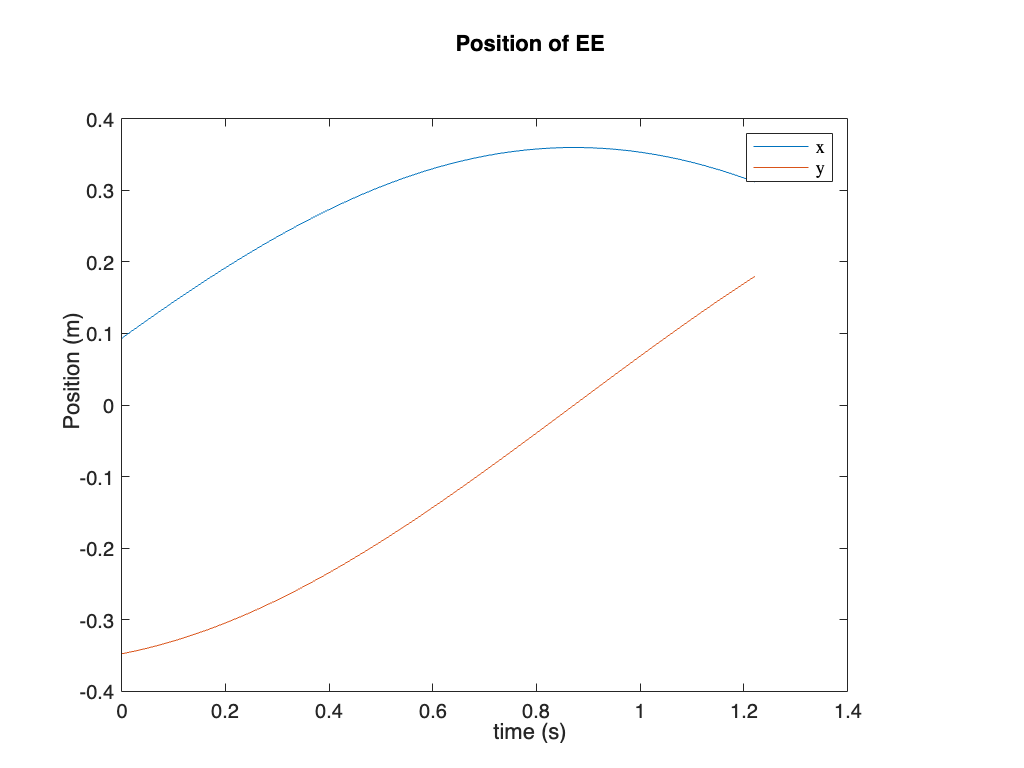


x_end_effector=L1*sin(values_q(3,:));
y_end_effector=-L1*cos(values_q(3,:));
plot(time,x_end_effector)
hold on
plot(time,y_end_effector)
title('Position of EE')
xlabel('time (s)')
ylabel('Position (m)')
legend('x','y','Interpreter','latex')
hold off

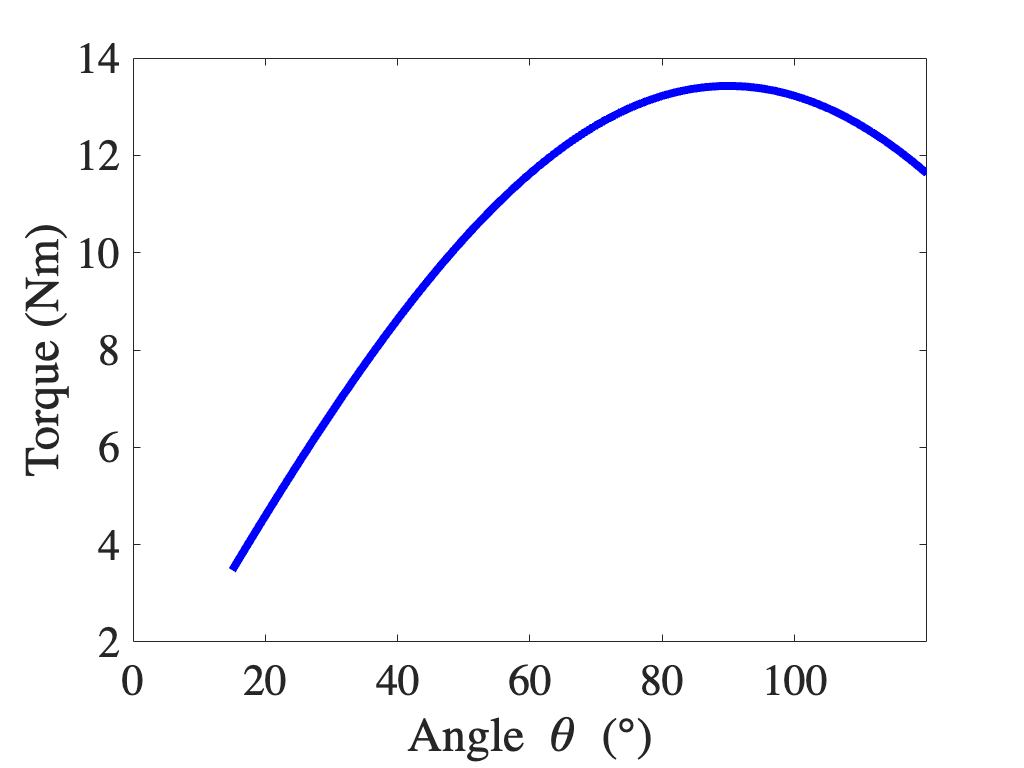


plot(values_q(3,:)*180/pi, Values_joint_reaction(3,:),"LineWidth",4,"Color",'b')
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'FontName','Times','fontsize',22)
xlabel('Angle \theta (\circ)')
ylabel('Torque (Nm)')

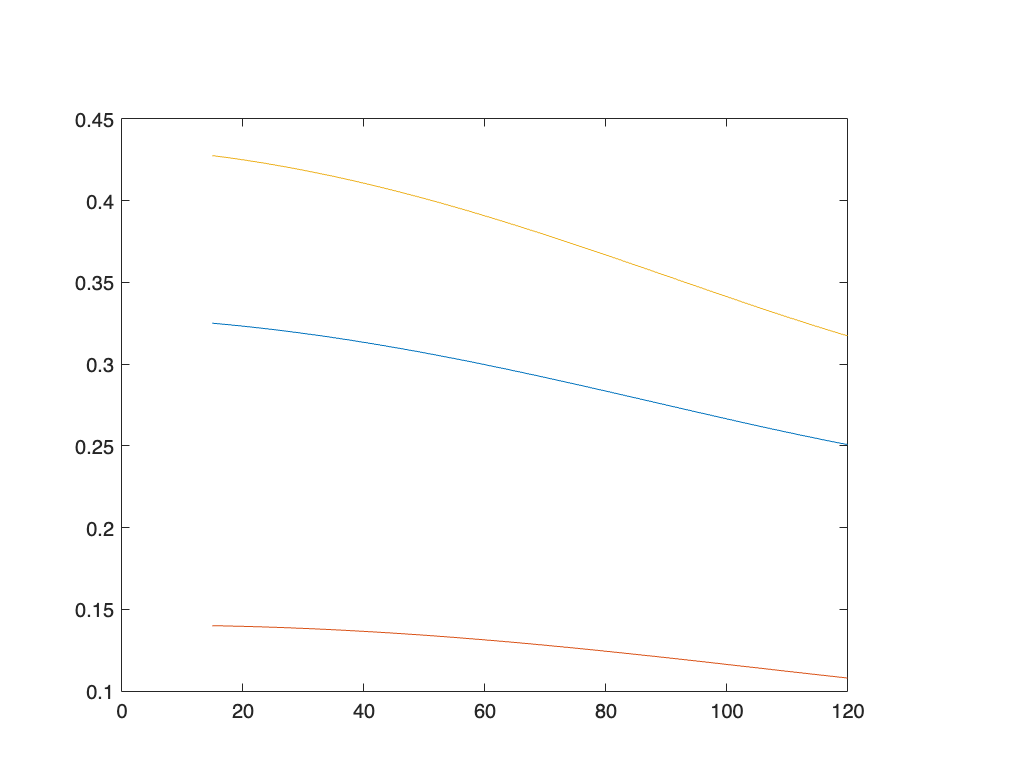

% Calculating length of each muscle group at a particular time
% Subscript 1 reperesents bicep brachii 2 for brachi 3 for wrist connected muscle
% a represents connection on grounded arm/bone and b for muscle connection on moving limb

a=0.01*[((28.015)^2+(1.202^2))^0.5;((11.61^2)+(0.68)^2)^0.5;((7.307^2)+(0.75^2))^0.5];
b=0.01*[((4.839^2)+(0.751^2))^0.5;((2.39^2)+(0.32^2))^0.5;((36^2)+(0.75^2))^0.5];

len=length(values_q);

l_mt(1,:)=((a(1)*ones(1,len)).^2 +(b(1)*ones(1,len)).^2-2*((a(1).*b(1))*(ones(1,len))).*cos(pi-ones(1,1)*values_q(3,:)-(11.29*pi/180))).^0.5;
l_mt(2,:)=((a(2)*ones(1,len)).^2 +(b(2)*ones(1,len)).^2-2*((a(2).*b(2))*(ones(1,len))).*cos(pi-ones(1,1)*values_q(3,:)+(4.274*pi/180))).^0.5;
l_mt(3,:)=((a(3)*ones(1,len)).^2 +(b(3)*ones(1,len)).^2-2*((a(3).*b(3))*(ones(1,len))).*cos(pi-ones(1,1)*values_q(3,:)-(10.535*pi/180))).^0.5;
% l^2=a^2+b^2-2abcos(theta)

alpha(1,:)=asin(a(1)*(ones(1,len)).*(sin(pi-ones(1,1)*values_q(3,:)-(11.29*pi/180)))./l_mt(1,:));
alpha(2,:)=asin(a(2)*(ones(1,len)).*(sin(pi-ones(1,1)*values_q(3,:)+(4.274*pi/180)))./l_mt(2,:));
alpha(3,:)=asin(a(3)*(ones(1,len)).*(sin(pi-ones(1,1)*values_q(3,:)-(10.535*pi/180)))./l_mt(3,:));
% sin alpha=a*sin(pi-theta)/l;

plot(values_q(3,:)*180/pi,l_mt)

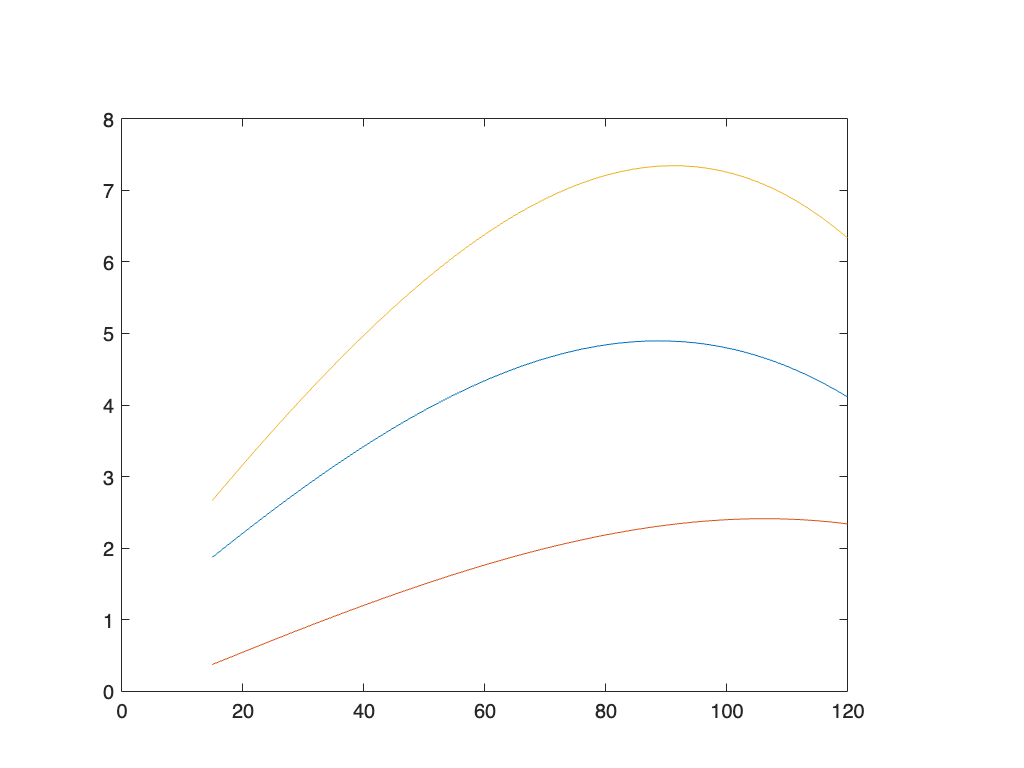

plot(values_q(3,:)*180/pi,100*b.*sin(alpha))

%l_m=l_mt-0.01*[11.8283;5.1511;22.8234]

flbic=[]; flbra=[]; flbrd=[];
fvbic=[]; fvbra=[]; fvbrd=[];
fplbic=[]; fplbra=[]; fplbrd=[];
% Optimum muscle length
lopt_bic=0.1405;
lopt_bra=0.0653;
lopt_brd=0.1724;

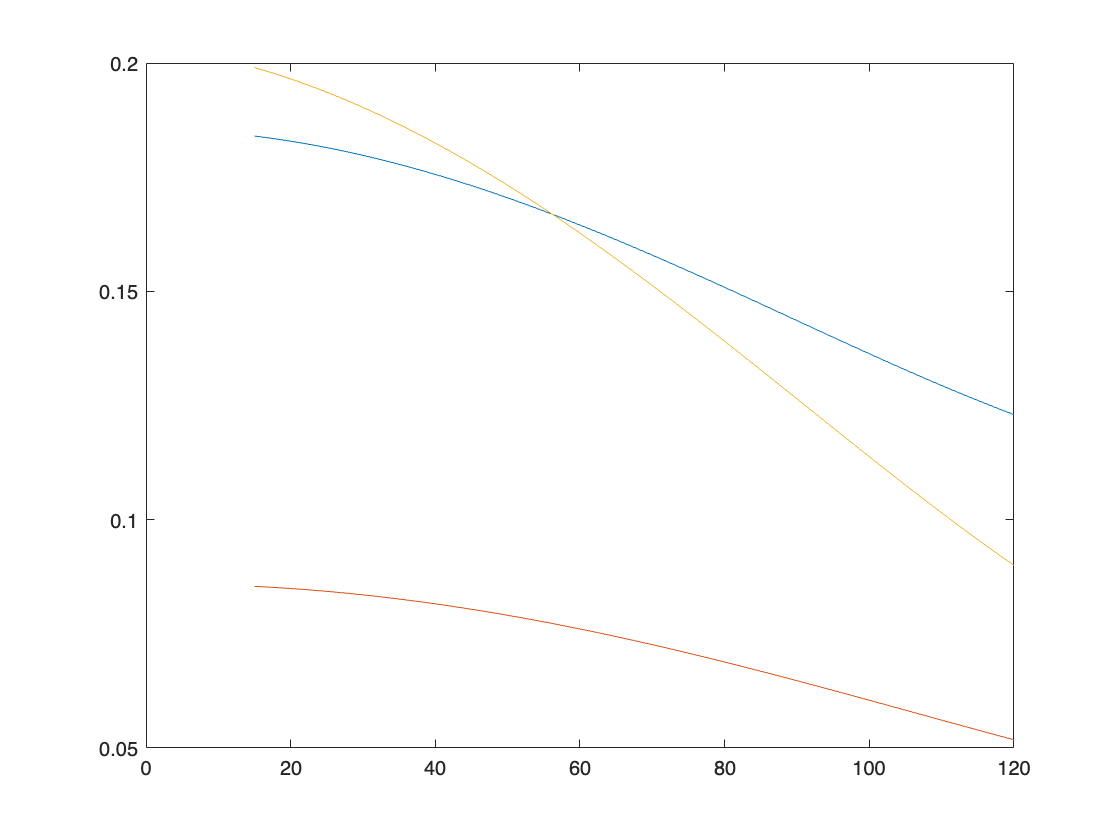

% Computing only muscle length
l_to=l_mt(:,1)-[0.184;0.0854;0.199];
l_tf=l_mt(:,len)-[0.123;0.0518;0.09];
y=(l_tf./l_to).^(1/(final_time));
x=l_to;
l_t=x.*y.^(time);
l_m=l_mt-l_t;

l_bic=l_m(1,:);
l_bra=l_m(2,:);
l_brd=l_m(3,:);

% Muscle and tendon length variation during motion
plot(values_q(3,:)*180/pi,l_m)

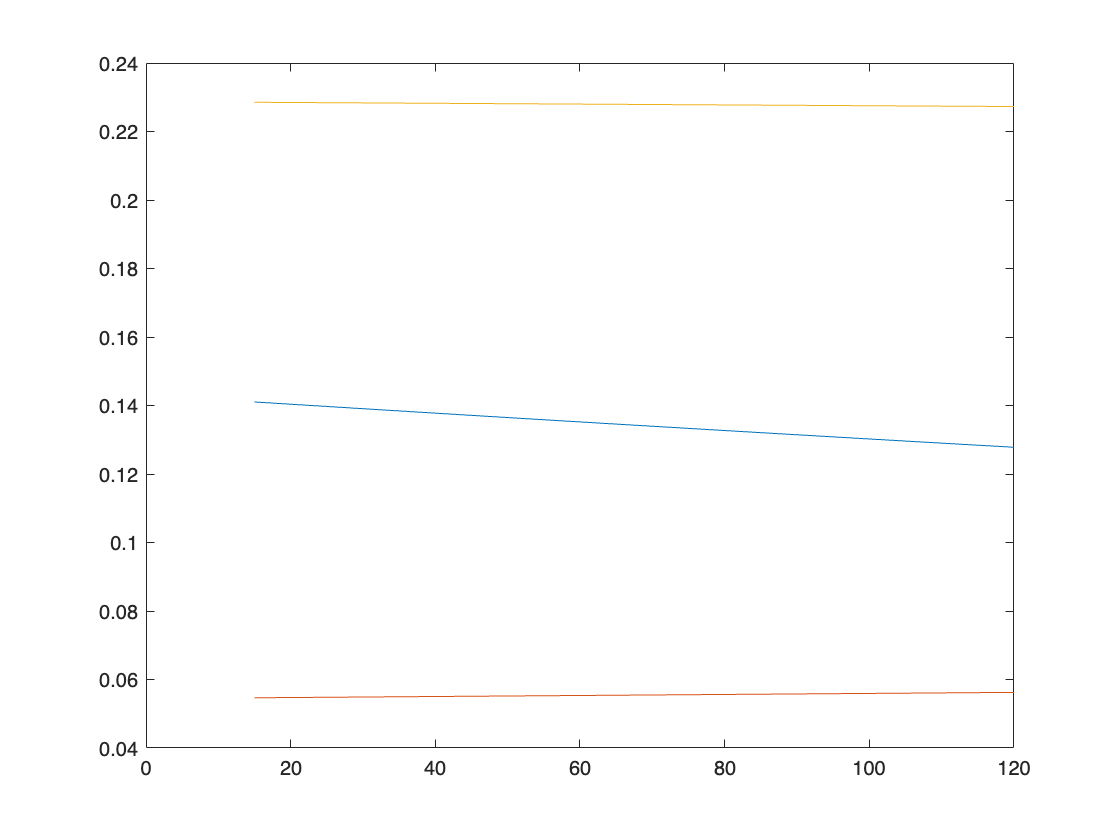

plot(values_q(3,:)*180/pi,l_t)

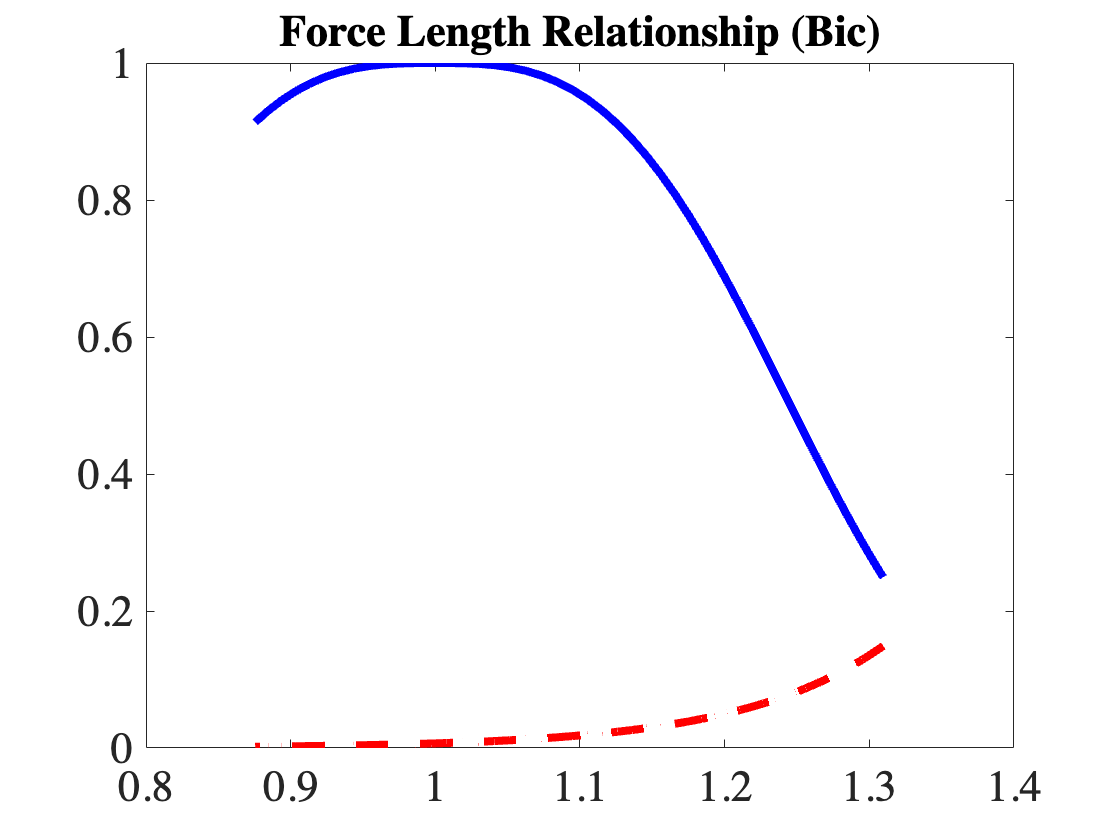


% Rate of change of muscle length
del_l=[];
for i = 1:len
    if (i==len)
        del_l(:,i)= abs(2*del_l(:,i-1)-del_l(:,i-2));
    else
        del_l(:,i)= abs(l_m(:,i)-l_m(:,i+1));
    end   
end
f_v = del_l/(final_time/len);

% Active and Passive force length parameters (adjust for model)
j=1;
for i=l_bic
    flbic(j)= exp(log(0.05)*abs((i-lopt_bic)/(lopt_bic*0.4))^3);
    fplbic(j)= exp(10*(i/lopt_bic-1))/exp(5);
    fvbic(j)= (-12*lopt_bic+f_v(1,j))/(-12*lopt_bic-5*f_v(1,j));
    j=j+1;
end

set1=[values_q(3,:)*180/pi;l_bic./lopt_bic;flbic;fplbic];

bic_pre_x=set1(2,1:37);
bic_pre=set1(3,1:37);

bic_opt_x=set1(2,38);
bic_opt=set1(3,38);
bic_post_x=set1(2,39:end);
bic_post=set1(3,39:end);
bic_p_pre=set1(4,1:37);
bic_p_opt=set1(4,38);
bic_p_post=set1(4,39:end);



plot(l_bic./lopt_bic,flbic,"LineWidth",4,"LineStyle","-","Color",'b')
hold on
plot(l_bic./lopt_bic,fplbic,"LineWidth",4,"LineStyle","--","Color",'r')
hold off
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'FontName','Times','fontsize',22)
xticklabels("auto")
yticklabels("auto")
%legend({'f_{a}(l_{m})','f_{p}(l_{m})'})
title('Force Length Relationship (Bic)',"FontSize",22)

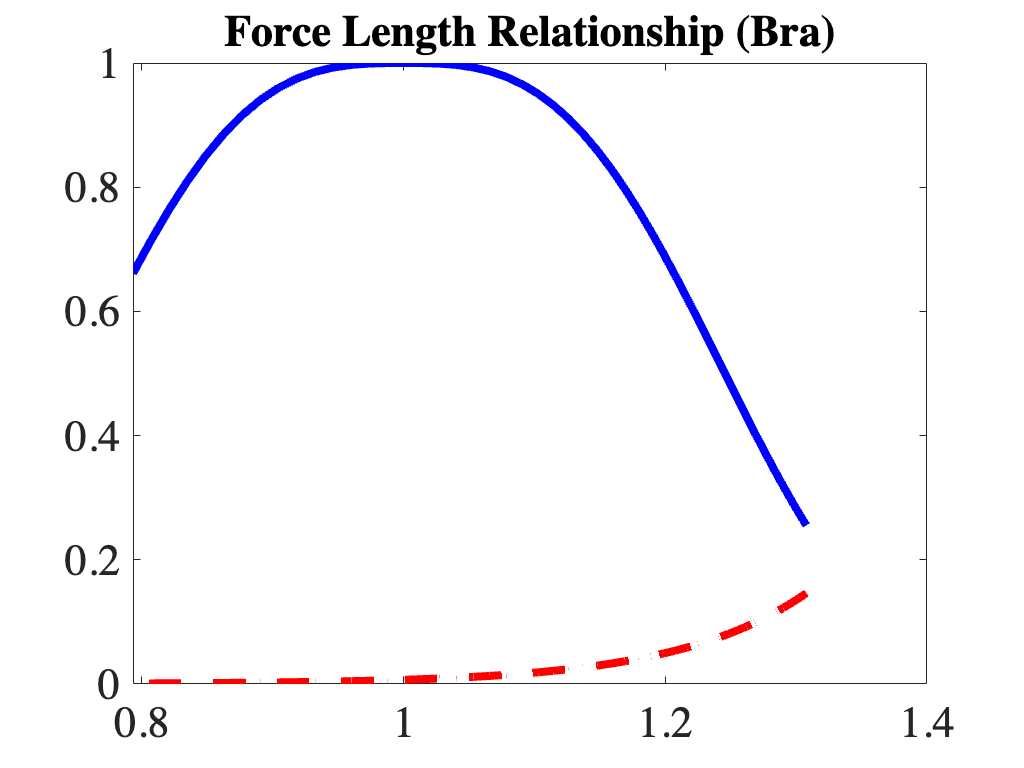

% xlabel('Normalized Length',"FontSize",22)
% ylabel('Normalized Force',"FontSize",22)
%print('-dpng','fl_bic.jpg','-r1200')

j=1;
for i=l_bra
    flbra(j)= exp(log(0.05)*abs((i-lopt_bra)/(lopt_bra*0.4))^3);
    fplbra(j)= exp(10*(i/lopt_bra-1))/exp(5);
    fvbra(j)= (-12*lopt_bra+f_v(2,j))/(-12*lopt_bra-5*f_v(2,j));
    j=j+1;
end
plot(l_bra./lopt_bra,flbra,"LineWidth",4,"LineStyle","-","Color",'b')
hold on
plot(l_bra./lopt_bra,fplbra,"LineWidth",4,"LineStyle","--","Color",'r')
hold off
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'FontName','Times','fontsize',22)
xticklabels("auto")
yticklabels("auto")
% legend({'f_{a}(l_{m})','f_{p}(l_{m})'})
title('Force Length Relationship (Bra)',"FontSize",22)

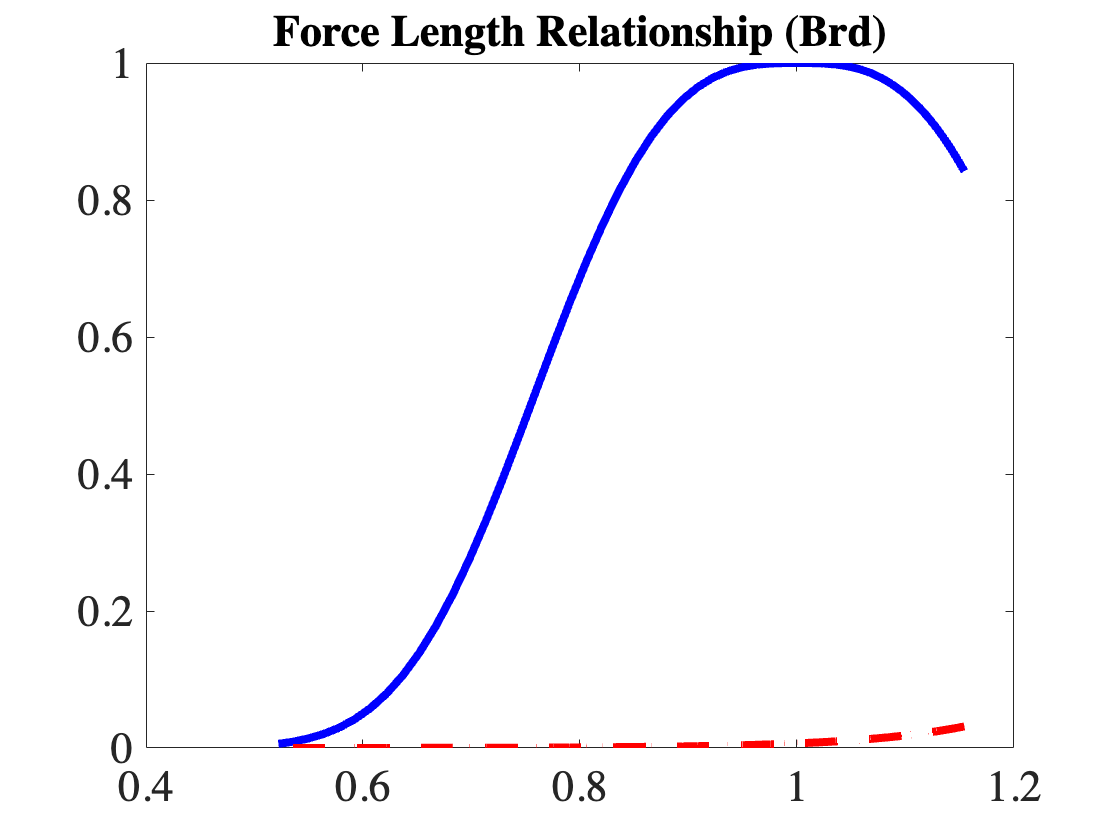

% xlabel('Normalized Length',"FontSize",22)
% ylabel('Normalized Force',"FontSize",22)
%print('-dpng','fl_bra.jpg','-r1200')

j=1;
for i=l_brd
    flbrd(j)= exp(log(0.05)*abs((i-lopt_brd)/(lopt_brd*0.4))^3);
    fplbrd(j)= exp(10*(i/lopt_brd-1))/exp(5);
    fvbrd(j)= (-12*lopt_brd+f_v(3,j))/(-12*lopt_brd-5*f_v(3,j));
    j=j+1;
end
plot(l_brd./lopt_brd,flbrd,"LineWidth",4,"LineStyle","-","Color",'b')
hold on
plot(l_brd./lopt_brd,fplbrd,"LineWidth",4,"LineStyle","--","Color",'r')
hold off
%set(findall(gcf,'-property','FontSize'),'FontSize',18)
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'FontName','Times','fontsize',22)
xticklabels("auto")
yticklabels("auto")
% legend({'f_{a}(l_{m})','f_{p}(l_{m})'})
title('Force Length Relationship (Brd)',"FontSize",22)

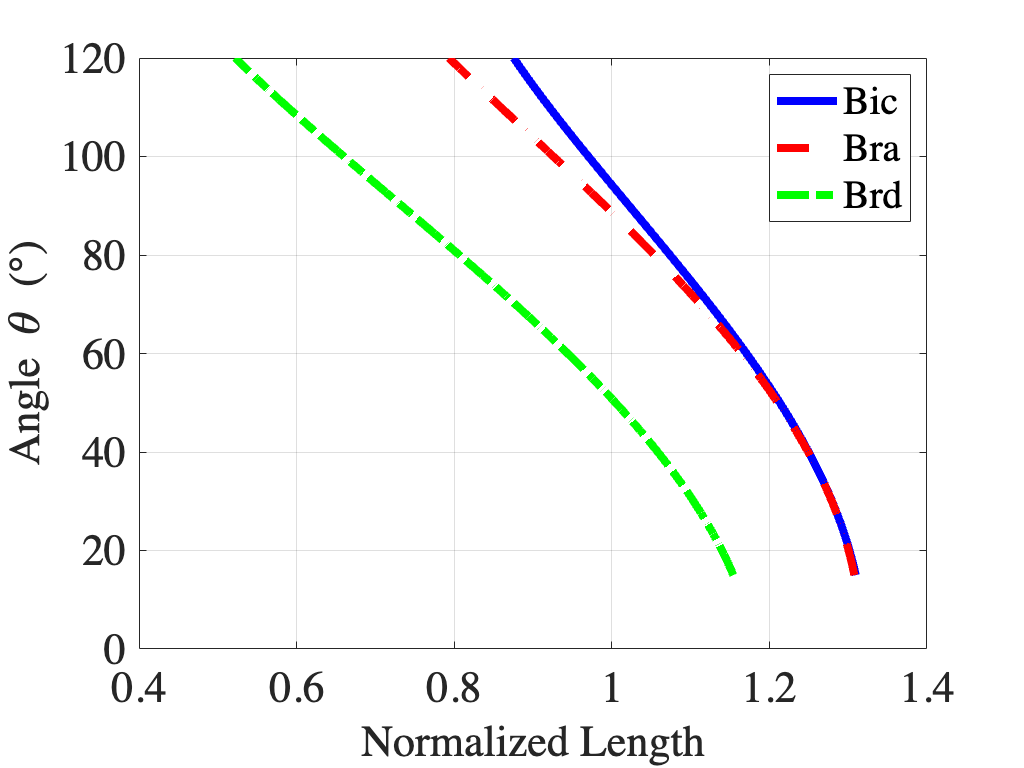

% xlabel('Normalized Length',"FontSize",22)
% ylabel('Normalized Force',"FontSize",22)
%print('-dpng','fl_brd.jpg','-r1200')

plot(l_bic./lopt_bic,values_q(3,:)*180/pi,"LineWidth",4,"LineStyle","-","Color",'b')
hold on
plot(l_bra./lopt_bra,values_q(3,:)*180/pi,"LineWidth",4,"LineStyle","--","Color",'r')
plot(l_brd./lopt_brd,values_q(3,:)*180/pi,"LineWidth",4,"LineStyle","-.","Color",'g')
hold off
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'FontName','Times','fontsize',22)
xticklabels("auto")
yticklabels("auto")
xlabel('Normalized Length',"FontSize",22)
ylabel('Angle \theta (\circ)',"FontSize",22)
legend({'Bic','Bra','Brd'})
grid on
print('-dpng','theta_l.jpg','-r1200')

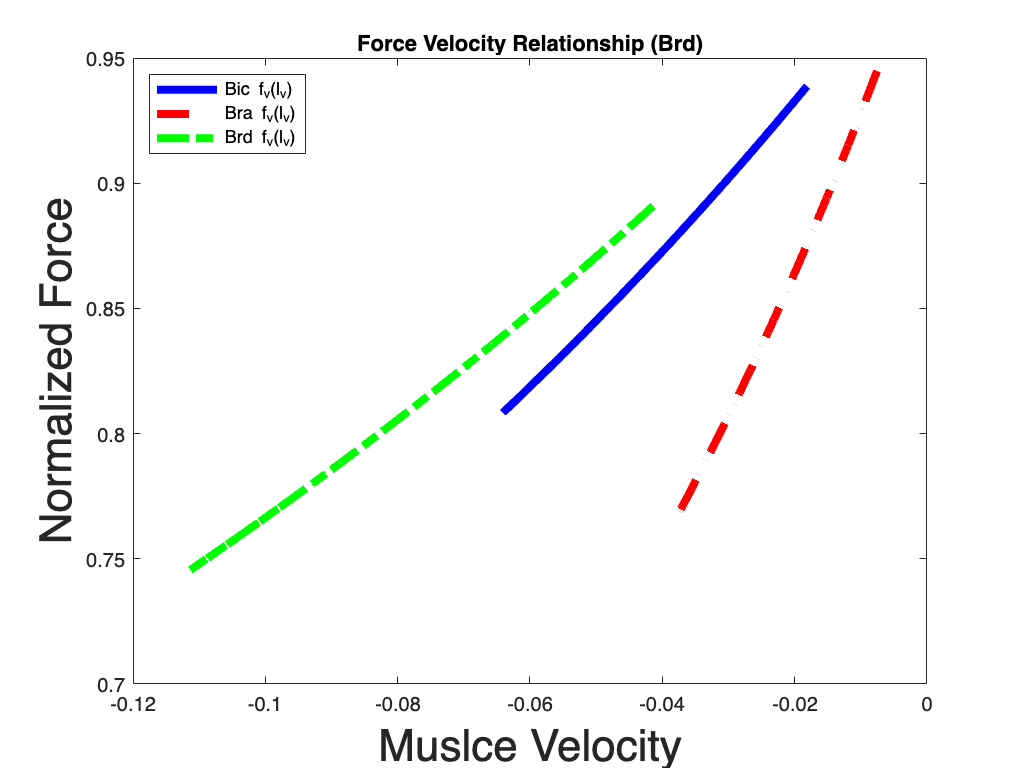




plot(-f_v(1,:),fvbic,"LineWidth",4,"LineStyle","-","Color",'b')
hold on
plot(-f_v(2,:),fvbra,"LineWidth",4,"LineStyle","--","Color",'r')
plot(-f_v(3,:),fvbrd,"LineWidth",4,"LineStyle","-.","Color",'g')
hold off
legend({'Bic f_{v}(l_{v})','Bra f_{v}(l_{v})','Brd f_{v}(l_{v})'},"Location","northwest")
title('Force Velocity Relationship (Brd)')
xlabel('Muslce Velocity',"FontSize",22)
ylabel('Normalized Force',"FontSize",22)

%print('-dpng','fv.jpg','-r1200')


% Optimizing the muscle forces

F1iso=444;
F2iso=209;
F3iso=771;

solution1=[];
FVal1=[];
T_F1=[];
act1=[];
solution2=[];
FVal2=[];
T_F2=[];
act2=[];

solution3=[];
FVal3=[];
T_F3=[];
act3=[];

solution4=[];
FVal4=[];
T_F4=[];
act4=[];

% J1 cost function

for j=1:len
    Cost1 = optimproblem;
    F1 = optimvar('F1','LowerBound',0,'UpperBound',F1iso);
    F2 = optimvar('F2','LowerBound',0,'UpperBound',F2iso);
    F3 = optimvar('F3','LowerBound',0,'UpperBound',F3iso);
    
    Cost1.Objective =F1^2+F2^2+F3^2; 
    Cost1.Constraints.cons1=F1*(b(1)*sin(alpha(1,j)))+F2*(b(2)*sin(alpha(2,j)))+F3*(b(3)*sin(alpha(3,j)))==Values_joint_reaction(3,j);
    Cost1.Constraints.cons5= F1<=F1iso*flbic(j)*fvbic(j)+F1iso*fplbic(j);
    Cost1.Constraints.cons6= F2<=F2iso*flbra(j)*fvbra(j)+F2iso*fplbra(j);
    Cost1.Constraints.cons7= F3<=F3iso*flbrd(j)*fvbrd(j)+F3iso*fplbrd(j);
  
    showproblem(Cost1);
    [sol,fval]=solve(Cost1);
    solution1=[solution1,[sol.F1;sol.F2;sol.F3]];
    T_F1(:,j)=[sol.F1*(b(1)*sin(alpha(1,j)));sol.F2*(b(2)*sin(alpha(2,j)));sol.F3*(b(3)*sin(alpha(3,j)))];
    FVal1=[FVal1,fval];
    if solution1(1,j)<F1iso*fplbic(j)
        act1(1,j)=0;
    else
        act1(1,j)=((solution1(1,j)-F1iso*fplbic(j))/(F1iso*flbic(j)*fvbic(j)))*100;
    end
    if solution1(2,j)<F2iso*fplbra(j)
        act1(2,j)=0;
    else
        act1(2,j)=((solution1(2,j)-F2iso*fplbra(j))/(F2iso*flbra(j)*fvbra(j)))*100;
    end
    if solution1(3,j)<F3iso*fplbrd(j)
        act1(3,j)=0;
    else
        act1(3,j)=((solution1(3,j)-F3iso*fplbrd(j))/(F3iso*flbrd(j)*fvbrd(j)))*100;
    end
    %act1(1,j)=solution1(1,j)/(F1iso)*100;
    %act1(2,j)=solution1(2,j)/(F2iso)*100;
    %act1(3,j)=solution1(3,j)/(F3iso)*100;

end


  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       ((F1.^2 + F2.^2) + F3.^2)


	subject to cons1:
       0.018711*F1 + 0.0037264*F2 + 0.026668*F3 == 3.475

	subject to cons5:
       F1 <= 170.0511

	subject to cons6:
       F2 <= 81.0065

	subject to cons7:
       F3 <= 602.7031

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using lsqlin.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       ((F1.^2 + F2.^2) + F3.^2)


	subject to cons1:
       0.020131*F1 + 0.0044495*F2 + 0.028764*F3 == 3.9479

	subject to cons5:
       F1 <= 171.6061

	subject to cons6:
       F2 <= 81.6237

	subject to cons7:
       F3 <= 607.1301

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using lsqlin.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       ((F1.^2 + F2.^2) + F3.^2)


	subject to cons1:
       0.021533*F1 + 0.0051691*F2 + 0.030836*F3 == 4.4155

	subject to cons5:
       F1 <= 173.5717

	subject to cons6:
       F2 <= 82.4356

	subject to cons7:
       F3 <= 611.6131

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using lsqlin.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       ((F1.^2 + F2.^2) + F3.^2)


	subject to cons1:
       0.022916*F1 + 0.0058848*F2 + 0.032884*F3 == 4.8772

	subject to cons5:
       F1 <= 175.9864

	subject to cons6:
       F2 <= 83.4603

	subject to cons7:
       F3 <= 616.0021

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using lsqlin.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       ((F1.^2 + F2.^2) + F3.^2)


	subject to cons1:
       0.024279*F1 + 0.0065958*F2 + 0.034905*F3 == 5.3323

	subject to cons5:
       F1 <= 178.8883

	subject to cons6:
       F2 <= 84.7167

	subject to cons7:
       F3 <= 620.1468

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using lsqlin.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       ((F1.^2 + F2.^2) + F3.^2)


	subject to cons1:
       0.025621*F1 + 0.0073017*F2 + 0.036897*F3 == 5.7803

	subject to cons5:
       F1 <= 182.3138

	subject to cons6:
       F2 <= 86.2234

	subject to cons7:
       F3 <= 623.9009

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using lsqlin.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       ((F1.^2 + F2.^2) + F3.^2)


	subject to cons1:
       0.02694*F1 + 0.0080018*F2 + 0.038859*F3 == 6.2205

	subject to cons5:
       F1 <= 186.2953

	subject to cons6:
       F2 <= 87.9982

	subject to cons7:
       F3 <= 627.1272

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using lsqlin.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       ((F1.^2 + F2.^2) + F3.^2)


	subject to cons1:
       0.028235*F1 + 0.0086956*F2 + 0.040788*F3 == 6.6523

	subject to cons5:
       F1 <= 190.86

	subject to cons6:
       F2 <= 90.0566

	subject to cons7:
       F3 <= 629.7025

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using lsqlin.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       ((F1.^2 + F2.^2) + F3.^2)


	subject to cons1:
       0.029505*F1 + 0.0093825*F2 + 0.042683*F3 == 7.0752

	subject to cons5:
       F1 <= 196.0273

	subject to cons6:
       F2 <= 92.411

	subject to cons7:
       F3 <= 631.5237

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using lsqlin.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       ((F1.^2 + F2.^2) + F3.^2)


	subject to cons1:
       0.030747*F1 + 0.010062*F2 + 0.044542*F3 == 7.4886

	subject to cons5:
       F1 <= 201.8072

	subject to cons6:
       F2 <= 95.0693

	subject to cons7:
       F3 <= 632.5134

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using lsqlin.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       ((F1.^2 + F2.^2) + F3.^2)


	subject to cons1:
       0.031962*F1 + 0.010733*F2 + 0.046363*F3 == 7.8919

	subject to cons5:
       F1 <= 208.1982

	subject to cons6:
       F2 <= 98.0338

	subject to cons7:
       F3 <= 632.6246

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using lsqlin.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       ((F1.^2 + F2.^2) + F3.^2)


	subject to cons1:
       0.033147*F1 + 0.011396*F2 + 0.048143*F3 == 8.2846

	subject to cons5:
       F1 <= 215.1861

	subject to cons6:
       F2 <= 101.3003

	subject to cons7:
       F3 <= 631.846

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using lsqlin.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       ((F1.^2 + F2.^2) + F3.^2)


	subject to cons1:
       0.034301*F1 + 0.012049*F2 + 0.049881*F3 == 8.6662

	subject to cons5:
       F1 <= 222.7421

	subject to cons6:
       F2 <= 104.8567

	subject to cons7:
       F3 <= 630.2054

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using lsqlin.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       ((F1.^2 + F2.^2) + F3.^2)


	subject to cons1:
       0.035423*F1 + 0.012692*F2 + 0.051576*F3 == 9.0362

	subject to cons5:
       F1 <= 230.8223

	subject to cons6:
       F2 <= 108.6823

	subject to cons7:
       F3 <= 627.7725

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using lsqlin.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       ((F1.^2 + F2.^2) + F3.^2)


	subject to cons1:
       0.03651*F1 + 0.013325*F2 + 0.053224*F3 == 9.394

	subject to cons5:
       F1 <= 239.3668

	subject to cons6:
       F2 <= 112.7473

	subject to cons7:
       F3 <= 624.6602

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using lsqlin.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       ((F1.^2 + F2.^2) + F3.^2)


	subject to cons1:
       0.037563*F1 + 0.013947*F2 + 0.054824*F3 == 9.7392

	subject to cons5:
       F1 <= 248.3005

	subject to cons6:
       F2 <= 117.0125

	subject to cons7:
       F3 <= 621.0254

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using lsqlin.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       ((F1.^2 + F2.^2) + F3.^2)


	subject to cons1:
       0.038579*F1 + 0.014557*F2 + 0.056374*F3 == 10.0714

	subject to cons5:
       F1 <= 257.5332

	subject to cons6:
       F2 <= 121.4296

	subject to cons7:
       F3 <= 617.0685

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using lsqlin.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       ((F1.^2 + F2.^2) + F3.^2)


	subject to cons1:
       0.039557*F1 + 0.015155*F2 + 0.057872*F3 == 10.39

	subject to cons5:
       F1 <= 266.9619

	subject to cons6:
       F2 <= 125.9414

	subject to cons7:
       F3 <= 613.0318

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using lsqlin.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       ((F1.^2 + F2.^2) + F3.^2)


	subject to cons1:
       0.040495*F1 + 0.01574*F2 + 0.059315*F3 == 10.6946

	subject to cons5:
       F1 <= 276.4728

	subject to cons6:
       F2 <= 130.4838

	subject to cons7:
       F3 <= 609.1113

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using lsqlin.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       ((F1.^2 + F2.^2) + F3.^2)


	subject to cons1:
       0.041392*F1 + 0.016311*F2 + 0.060702*F3 == 10.9849

	subject to cons5:
       F1 <= 285.9444

	subject to cons6:
       F2 <= 134.9869

	subject to cons7:
       F3 <= 605.0973

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using lsqlin.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       ((F1.^2 + F2.^2) + F3.^2)


	subject to cons1:
       0.042247*F1 + 0.016867*F2 + 0.06203*F3 == 11.2604

	subject to cons5:
       F1 <= 295.2515

	subject to cons6:
       F2 <= 139.3774

	subject to cons7:
       F3 <= 600.6231

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using lsqlin.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       ((F1.^2 + F2.^2) + F3.^2)


	subject to cons1:
       0.043058*F1 + 0.017409*F2 + 0.063297*F3 == 11.5208

	subject to cons5:
       F1 <= 304.269

	subject to cons6:
       F2 <= 143.5815

	subject to cons7:
       F3 <= 595.2874

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using lsqlin.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       ((F1.^2 + F2.^2) + F3.^2)


	subject to cons1:
       0.043824*F1 + 0.017935*F2 + 0.064501*F3 == 11.7657

	subject to cons5:
       F1 <= 312.8766

	subject to cons6:
       F2 <= 147.5276

	subject to cons7:
       F3 <= 588.6621

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using lsqlin.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       ((F1.^2 + F2.^2) + F3.^2)


	subject to cons1:
       0.044542*F1 + 0.018445*F2 + 0.06564*F3 == 11.9949

	subject to cons5:
       F1 <= 320.9629

	subject to cons6:
       F2 <= 151.1497

	subject to cons7:
       F3 <= 580.3044

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using lsqlin.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       ((F1.^2 + F2.^2) + F3.^2)


	subject to cons1:
       0.045213*F1 + 0.018938*F2 + 0.066711*F3 == 12.2079

	subject to cons5:
       F1 <= 328.4303

	subject to cons6:
       F2 <= 154.3903

	subject to cons7:
       F3 <= 569.7738

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using lsqlin.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       ((F1.^2 + F2.^2) + F3.^2)


	subject to cons1:
       0.045833*F1 + 0.019413*F2 + 0.067712*F3 == 12.4045

	subject to cons5:
       F1 <= 335.1981

	subject to cons6:
       F2 <= 157.2034

	subject to cons7:
       F3 <= 556.6544

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using lsqlin.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       ((F1.^2 + F2.^2) + F3.^2)


	subject to cons1:
       0.046402*F1 + 0.01987*F2 + 0.068642*F3 == 12.5844

	subject to cons5:
       F1 <= 341.206

	subject to cons6:
       F2 <= 159.5567

	subject to cons7:
       F3 <= 540.5818

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using lsqlin.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       ((F1.^2 + F2.^2) + F3.^2)


	subject to cons1:
       0.046918*F1 + 0.020307*F2 + 0.069497*F3 == 12.7475

	subject to cons5:
       F1 <= 346.4165

	subject to cons6:
       F2 <= 161.4339

	subject to cons7:
       F3 <= 521.2733

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using lsqlin.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       ((F1.^2 + F2.^2) + F3.^2)


	subject to cons1:
       0.04738*F1 + 0.020725*F2 + 0.070274*F3 == 12.8934

	subject to cons5:
       F1 <= 350.8156

	subject to cons6:
       F2 <= 162.8353

	subject to cons7:
       F3 <= 498.5595

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using lsqlin.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       ((F1.^2 + F2.^2) + F3.^2)


	subject to cons1:
       0.047786*F1 + 0.021123*F2 + 0.070973*F3 == 13.022

	subject to cons5:
       F1 <= 354.4138

	subject to cons6:
       F2 <= 163.7786

	subject to cons7:
       F3 <= 472.4143

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using lsqlin.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       ((F1.^2 + F2.^2) + F3.^2)


	subject to cons1:
       0.048135*F1 + 0.021499*F2 + 0.071591*F3 == 13.1331

	subject to cons5:
       F1 <= 357.2452

	subject to cons6:
       F2 <= 164.2984

	subject to cons7:
       F3 <= 442.9792

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using lsqlin.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       ((F1.^2 + F2.^2) + F3.^2)


	subject to cons1:
       0.048425*F1 + 0.021853*F2 + 0.072124*F3 == 13.2266

	subject to cons5:
       F1 <= 359.3655

	subject to cons6:
       F2 <= 164.4453

	subject to cons7:
       F3 <= 410.5778

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using lsqlin.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       ((F1.^2 + F2.^2) + F3.^2)


	subject to cons1:
       0.048654*F1 + 0.022185*F2 + 0.072571*F3 == 13.3023

	subject to cons5:
       F1 <= 360.8504

	subject to cons6:
       F2 <= 164.2845

	subject to cons7:
       F3 <= 375.7168

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using lsqlin.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       ((F1.^2 + F2.^2) + F3.^2)


	subject to cons1:
       0.048823*F1 + 0.022493*F2 + 0.07293*F3 == 13.3601

	subject to cons5:
       F1 <= 361.7925

	subject to cons6:
       F2 <= 163.8935

	subject to cons7:
       F3 <= 339.0702

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using lsqlin.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       ((F1.^2 + F2.^2) + F3.^2)


	subject to cons1:
       0.048928*F1 + 0.022776*F2 + 0.073197*F3 == 13.4

	subject to cons5:
       F1 <= 362.2979

	subject to cons6:
       F2 <= 163.3608

	subject to cons7:
       F3 <= 301.4456

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using lsqlin.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       ((F1.^2 + F2.^2) + F3.^2)


	subject to cons1:
       0.048969*F1 + 0.023035*F2 + 0.073371*F3 == 13.4219

	subject to cons5:
       F1 <= 362.4834

	subject to cons6:
       F2 <= 162.7834

	subject to cons7:
       F3 <= 263.7354

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using lsqlin.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       ((F1.^2 + F2.^2) + F3.^2)


	subject to cons1:
       0.048944*F1 + 0.023268*F2 + 0.073449*F3 == 13.4258

	subject to cons5:
       F1 <= 362.4728

	subject to cons6:
       F2 <= 162.2362

	subject to cons7:
       F3 <= 226.8543

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using lsqlin.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       ((F1.^2 + F2.^2) + F3.^2)


	subject to cons1:
       0.048853*F1 + 0.023474*F2 + 0.07343*F3 == 13.4116

	subject to cons5:
       F1 <= 362.3942

	subject to cons6:
       F2 <= 161.6501

	subject to cons7:
       F3 <= 191.6729

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using lsqlin.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       ((F1.^2 + F2.^2) + F3.^2)


	subject to cons1:
       0.048693*F1 + 0.023653*F2 + 0.07331*F3 == 13.3794

	subject to cons5:
       F1 <= 362.3763

	subject to cons6:
       F2 <= 160.9076

	subject to cons7:
       F3 <= 158.9534

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using lsqlin.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       ((F1.^2 + F2.^2) + F3.^2)


	subject to cons1:
       0.048464*F1 + 0.023804*F2 + 0.073088*F3 == 13.3293

	subject to cons5:
       F1 <= 362.4627

	subject to cons6:
       F2 <= 159.8887

	subject to cons7:
       F3 <= 129.2965

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using lsqlin.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       ((F1.^2 + F2.^2) + F3.^2)


	subject to cons1:
       0.048165*F1 + 0.023926*F2 + 0.072761*F3 == 13.2612

	subject to cons5:
       F1 <= 362.5418

	subject to cons6:
       F2 <= 158.4749

	subject to cons7:
       F3 <= 103.1057

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using lsqlin.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       ((F1.^2 + F2.^2) + F3.^2)


	subject to cons1:
       0.047794*F1 + 0.024018*F2 + 0.072327*F3 == 13.1753

	subject to cons5:
       F1 <= 362.4909

	subject to cons6:
       F2 <= 156.5523

	subject to cons7:
       F3 <= 80.5741

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using lsqlin.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       ((F1.^2 + F2.^2) + F3.^2)


	subject to cons1:
       0.047352*F1 + 0.02408*F2 + 0.071785*F3 == 13.0718

	subject to cons5:
       F1 <= 362.1952

	subject to cons6:
       F2 <= 154.0173

	subject to cons7:
       F3 <= 61.6933

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using lsqlin.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       ((F1.^2 + F2.^2) + F3.^2)


	subject to cons1:
       0.046836*F1 + 0.02411*F2 + 0.071133*F3 == 12.9506

	subject to cons5:
       F1 <= 361.5502

	subject to cons6:
       F2 <= 150.7818

	subject to cons7:
       F3 <= 46.2809

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using lsqlin.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       ((F1.^2 + F2.^2) + F3.^2)


	subject to cons1:
       0.046246*F1 + 0.024108*F2 + 0.070369*F3 == 12.8121

	subject to cons5:
       F1 <= 360.4649

	subject to cons6:
       F2 <= 146.7792

	subject to cons7:
       F3 <= 34.0229

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using lsqlin.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       ((F1.^2 + F2.^2) + F3.^2)


	subject to cons1:
       0.045582*F1 + 0.024074*F2 + 0.06949*F3 == 12.6564

	subject to cons5:
       F1 <= 358.8641

	subject to cons6:
       F2 <= 141.9698

	subject to cons7:
       F3 <= 24.52

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using lsqlin.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       ((F1.^2 + F2.^2) + F3.^2)


	subject to cons1:
       0.044844*F1 + 0.024006*F2 + 0.068497*F3 == 12.4837

	subject to cons5:
       F1 <= 356.691

	subject to cons6:
       F2 <= 136.3454

	subject to cons7:
       F3 <= 17.3353

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using lsqlin.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       ((F1.^2 + F2.^2) + F3.^2)


	subject to cons1:
       0.04403*F1 + 0.023903*F2 + 0.067388*F3 == 12.2942

	subject to cons5:
       F1 <= 353.9091

	subject to cons6:
       F2 <= 129.9326

	subject to cons7:
       F3 <= 12.0336

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using lsqlin.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       ((F1.^2 + F2.^2) + F3.^2)


	subject to cons1:
       0.043141*F1 + 0.023766*F2 + 0.066161*F3 == 12.0881

	subject to cons5:
       F1 <= 350.5034

	subject to cons6:
       F2 <= 122.7938

	subject to cons7:
       F3 <= 8.2113

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using lsqlin.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       ((F1.^2 + F2.^2) + F3.^2)


	subject to cons1:
       0.042176*F1 + 0.023593*F2 + 0.064817*F3 == 11.8659

	subject to cons5:
       F1 <= 346.4808

	subject to cons6:
       F2 <= 115.0257

	subject to cons7:
       F3 <= 5.516

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using lsqlin.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       ((F1.^2 + F2.^2) + F3.^2)


	subject to cons1:
       0.041137*F1 + 0.023384*F2 + 0.063354*F3 == 11.6277

	subject to cons5:
       F1 <= 341.7457

	subject to cons6:
       F2 <= 106.7167

	subject to cons7:
       F3 <= 3.6526

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using lsqlin.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



% J2 cost function

for j=1:len    
    Cost2 = optimproblem;
    F1 = optimvar('F1','LowerBound',0,'UpperBound',F1iso);
    F2 = optimvar('F2','LowerBound',0,'UpperBound',F2iso);
    F3 = optimvar('F3','LowerBound',0,'UpperBound',F3iso);
    
    Cost2.Objective = ((F1*del_l(1,j))^2+(F2*del_l(2,j))^2+(F3*del_l(3,j))^2).^(1/2); 
    Cost2.Constraints.cons1=F1*(b(1)*sin(alpha(1,j)))+F2*(b(2)*sin(alpha(2,j)))+F3*(b(3)*sin(alpha(3,j)))==Values_joint_reaction(3,j);
    Cost2.Constraints.cons5= F1<=F1iso*flbic(j)*fvbic(j)+F1iso*fplbic(j);
    Cost2.Constraints.cons6= F2<=F2iso*flbra(j)*fvbra(j)+F2iso*fplbra(j);
    Cost2.Constraints.cons7= F3<=F3iso*flbrd(j)*fvbrd(j)+F3iso*fplbrd(j);
    
    showproblem(Cost2);
    [sol,fval]=solve(Cost2,sol);
    solution2=[solution2,[sol.F1;sol.F2;sol.F3]];
    T_F2(:,j)=[sol.F1*(b(1)*sin(alpha(1,j)));sol.F2*(b(2)*sin(alpha(2,j)));sol.F3*(b(3)*sin(alpha(3,j)))];
    FVal2=[FVal2,fval];
    if solution2(1,j)<F1iso*fplbic(j)
        act2(1,j)=0;
    else
        act2(1,j)=((solution2(1,j)-F1iso*fplbic(j))/(F1iso*flbic(j)*fvbic(j)))*100;
    end
    if solution2(2,j)<F2iso*fplbra(j)
        act2(2,j)=0;
    else
        act2(2,j)=((solution2(2,j)-F2iso*fplbra(j))/(F2iso*flbra(j)*fvbra(j)))*100;
    end
    if solution2(3,j)<F3iso*fplbrd(j)
        act2(3,j)=0;
    else
        act2(3,j)=((solution2(3,j)-F3iso*fplbrd(j))/(F3iso*flbrd(j)*fvbrd(j)))*100;
    end
    %act2(1,j)=solution2(1,j)/(F1iso)*100;
    %act2(2,j)=solution2(2,j)/(F2iso)*100;
    %act2(3,j)=solution2(3,j)/(F3iso)*100;

end


  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 .* 0.00043433).^2 + (F2 .* 0.00018092).^2) + (F3 .* 0.00099099).^2).^0.5


	subject to cons1:
       0.018711*F1 + 0.0037264*F2 + 0.026668*F3 == 3.475

	subject to cons5:
       F1 <= 170.0511

	subject to cons6:
       F2 <= 81.0065

	subject to cons7:
       F3 <= 602.7031

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 .* 0.00048659).^2 + (F2 .* 0.00020738).^2) + (F3 .* 0.0010674).^2).^0.5


	subject to cons1:
       0.020131*F1 + 0.0044495*F2 + 0.028764*F3 == 3.9479

	subject to cons5:
       F1 <= 171.6061

	subject to cons6:
       F2 <= 81.6237

	subject to cons7:
       F3 <= 607.1301

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 .* 0.00053818).^2 + (F2 .* 0.0002337).^2) + (F3 .* 0.0011429).^2).^0.5


	subject to cons1:
       0.021533*F1 + 0.0051691*F2 + 0.030836*F3 == 4.4155

	subject to cons5:
       F1 <= 173.5717

	subject to cons6:
       F2 <= 82.4356

	subject to cons7:
       F3 <= 611.6131

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Feasible point with lower objective function value found, but optimality criteria not satisfied. See output.bestfeasible..


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<


  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 .* 0.00058906).^2 + (F2 .* 0.00025987).^2) + (F3 .* 0.0012175).^2).^0.5


	subject to cons1:
       0.022916*F1 + 0.0058848*F2 + 0.032884*F3 == 4.8772

	subject to cons5:
       F1 <= 175.9864

	subject to cons6:
       F2 <= 83.4603

	subject to cons7:
       F3 <= 616.0021

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Feasible point with lower objective function value found, but optimality criteria not satisfied. See output.bestfeasible..


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<


  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 .* 0.00063918).^2 + (F2 .* 0.00028585).^2) + (F3 .* 0.001291).^2).^0.5


	subject to cons1:
       0.024279*F1 + 0.0065958*F2 + 0.034905*F3 == 5.3323

	subject to cons5:
       F1 <= 178.8883

	subject to cons6:
       F2 <= 84.7167

	subject to cons7:
       F3 <= 620.1468

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 .* 0.00068849).^2 + (F2 .* 0.00031164).^2) + (F3 .* 0.0013635).^2).^0.5


	subject to cons1:
       0.025621*F1 + 0.0073017*F2 + 0.036897*F3 == 5.7803

	subject to cons5:
       F1 <= 182.3138

	subject to cons6:
       F2 <= 86.2234

	subject to cons7:
       F3 <= 623.9009

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 .* 0.00073694).^2 + (F2 .* 0.0003372).^2) + (F3 .* 0.0014348).^2).^0.5


	subject to cons1:
       0.02694*F1 + 0.0080018*F2 + 0.038859*F3 == 6.2205

	subject to cons5:
       F1 <= 186.2953

	subject to cons6:
       F2 <= 87.9982

	subject to cons7:
       F3 <= 627.1272

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 .* 0.00078448).^2 + (F2 .* 0.00036252).^2) + (F3 .* 0.0015049).^2).^0.5


	subject to cons1:
       0.028235*F1 + 0.0086956*F2 + 0.040788*F3 == 6.6523

	subject to cons5:
       F1 <= 190.86

	subject to cons6:
       F2 <= 90.0566

	subject to cons7:
       F3 <= 629.7025

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 .* 0.00083106).^2 + (F2 .* 0.00038758).^2) + (F3 .* 0.0015737).^2).^0.5


	subject to cons1:
       0.029505*F1 + 0.0093825*F2 + 0.042683*F3 == 7.0752

	subject to cons5:
       F1 <= 196.0273

	subject to cons6:
       F2 <= 92.411

	subject to cons7:
       F3 <= 631.5237

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 .* 0.00087664).^2 + (F2 .* 0.00041235).^2) + (F3 .* 0.0016412).^2).^0.5


	subject to cons1:
       0.030747*F1 + 0.010062*F2 + 0.044542*F3 == 7.4886

	subject to cons5:
       F1 <= 201.8072

	subject to cons6:
       F2 <= 95.0693

	subject to cons7:
       F3 <= 632.5134

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 .* 0.00092115).^2 + (F2 .* 0.00043682).^2) + (F3 .* 0.0017072).^2).^0.5


	subject to cons1:
       0.031962*F1 + 0.010733*F2 + 0.046363*F3 == 7.8919

	subject to cons5:
       F1 <= 208.1982

	subject to cons6:
       F2 <= 98.0338

	subject to cons7:
       F3 <= 632.6246

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 .* 0.00096456).^2 + (F2 .* 0.00046095).^2) + (F3 .* 0.0017716).^2).^0.5


	subject to cons1:
       0.033147*F1 + 0.011396*F2 + 0.048143*F3 == 8.2846

	subject to cons5:
       F1 <= 215.1861

	subject to cons6:
       F2 <= 101.3003

	subject to cons7:
       F3 <= 631.846

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 .* 0.0010068).^2 + (F2 .* 0.00048473).^2) + (F3 .* 0.0018346).^2).^0.5


	subject to cons1:
       0.034301*F1 + 0.012049*F2 + 0.049881*F3 == 8.6662

	subject to cons5:
       F1 <= 222.7421

	subject to cons6:
       F2 <= 104.8567

	subject to cons7:
       F3 <= 630.2054

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 .* 0.0010478).^2 + (F2 .* 0.00050814).^2) + (F3 .* 0.0018958).^2).^0.5


	subject to cons1:
       0.035423*F1 + 0.012692*F2 + 0.051576*F3 == 9.0362

	subject to cons5:
       F1 <= 230.8223

	subject to cons6:
       F2 <= 108.6823

	subject to cons7:
       F3 <= 627.7725

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 .* 0.0010876).^2 + (F2 .* 0.00053116).^2) + (F3 .* 0.0019554).^2).^0.5


	subject to cons1:
       0.03651*F1 + 0.013325*F2 + 0.053224*F3 == 9.394

	subject to cons5:
       F1 <= 239.3668

	subject to cons6:
       F2 <= 112.7473

	subject to cons7:
       F3 <= 624.6602

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 .* 0.001126).^2 + (F2 .* 0.00055375).^2) + (F3 .* 0.0020131).^2).^0.5


	subject to cons1:
       0.037563*F1 + 0.013947*F2 + 0.054824*F3 == 9.7392

	subject to cons5:
       F1 <= 248.3005

	subject to cons6:
       F2 <= 117.0125

	subject to cons7:
       F3 <= 621.0254

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 .* 0.0011631).^2 + (F2 .* 0.0005759).^2) + (F3 .* 0.002069).^2).^0.5


	subject to cons1:
       0.038579*F1 + 0.014557*F2 + 0.056374*F3 == 10.0714

	subject to cons5:
       F1 <= 257.5332

	subject to cons6:
       F2 <= 121.4296

	subject to cons7:
       F3 <= 617.0685

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 .* 0.0011988).^2 + (F2 .* 0.00059759).^2) + (F3 .* 0.0021229).^2).^0.5


	subject to cons1:
       0.039557*F1 + 0.015155*F2 + 0.057872*F3 == 10.39

	subject to cons5:
       F1 <= 266.9619

	subject to cons6:
       F2 <= 125.9414

	subject to cons7:
       F3 <= 613.0318

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 .* 0.0012329).^2 + (F2 .* 0.00061879).^2) + (F3 .* 0.0021747).^2).^0.5


	subject to cons1:
       0.040495*F1 + 0.01574*F2 + 0.059315*F3 == 10.6946

	subject to cons5:
       F1 <= 276.4728

	subject to cons6:
       F2 <= 130.4838

	subject to cons7:
       F3 <= 609.1113

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 .* 0.0012656).^2 + (F2 .* 0.00063947).^2) + (F3 .* 0.0022245).^2).^0.5


	subject to cons1:
       0.041392*F1 + 0.016311*F2 + 0.060702*F3 == 10.9849

	subject to cons5:
       F1 <= 285.9444

	subject to cons6:
       F2 <= 134.9869

	subject to cons7:
       F3 <= 605.0973

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 .* 0.0012966).^2 + (F2 .* 0.00065962).^2) + (F3 .* 0.0022721).^2).^0.5


	subject to cons1:
       0.042247*F1 + 0.016867*F2 + 0.06203*F3 == 11.2604

	subject to cons5:
       F1 <= 295.2515

	subject to cons6:
       F2 <= 139.3774

	subject to cons7:
       F3 <= 600.6231

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 .* 0.001326).^2 + (F2 .* 0.00067921).^2) + (F3 .* 0.0023174).^2).^0.5


	subject to cons1:
       0.043058*F1 + 0.017409*F2 + 0.063297*F3 == 11.5208

	subject to cons5:
       F1 <= 304.269

	subject to cons6:
       F2 <= 143.5815

	subject to cons7:
       F3 <= 595.2874

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 .* 0.0013538).^2 + (F2 .* 0.00069822).^2) + (F3 .* 0.0023603).^2).^0.5


	subject to cons1:
       0.043824*F1 + 0.017935*F2 + 0.064501*F3 == 11.7657

	subject to cons5:
       F1 <= 312.8766

	subject to cons6:
       F2 <= 147.5276

	subject to cons7:
       F3 <= 588.6621

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 .* 0.0013798).^2 + (F2 .* 0.00071661).^2) + (F3 .* 0.0024008).^2).^0.5


	subject to cons1:
       0.044542*F1 + 0.018445*F2 + 0.06564*F3 == 11.9949

	subject to cons5:
       F1 <= 320.9629

	subject to cons6:
       F2 <= 151.1497

	subject to cons7:
       F3 <= 580.3044

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 .* 0.0014039).^2 + (F2 .* 0.00073437).^2) + (F3 .* 0.0024388).^2).^0.5


	subject to cons1:
       0.045213*F1 + 0.018938*F2 + 0.066711*F3 == 12.2079

	subject to cons5:
       F1 <= 328.4303

	subject to cons6:
       F2 <= 154.3903

	subject to cons7:
       F3 <= 569.7738

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 .* 0.0014263).^2 + (F2 .* 0.00075147).^2) + (F3 .* 0.0024742).^2).^0.5


	subject to cons1:
       0.045833*F1 + 0.019413*F2 + 0.067712*F3 == 12.4045

	subject to cons5:
       F1 <= 335.1981

	subject to cons6:
       F2 <= 157.2034

	subject to cons7:
       F3 <= 556.6544

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 .* 0.0014467).^2 + (F2 .* 0.00076788).^2) + (F3 .* 0.0025069).^2).^0.5


	subject to cons1:
       0.046402*F1 + 0.01987*F2 + 0.068642*F3 == 12.5844

	subject to cons5:
       F1 <= 341.206

	subject to cons6:
       F2 <= 159.5567

	subject to cons7:
       F3 <= 540.5818

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 .* 0.0014651).^2 + (F2 .* 0.00078359).^2) + (F3 .* 0.0025368).^2).^0.5


	subject to cons1:
       0.046918*F1 + 0.020307*F2 + 0.069497*F3 == 12.7475

	subject to cons5:
       F1 <= 346.4165

	subject to cons6:
       F2 <= 161.4339

	subject to cons7:
       F3 <= 521.2733

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 .* 0.0014815).^2 + (F2 .* 0.00079855).^2) + (F3 .* 0.0025639).^2).^0.5


	subject to cons1:
       0.04738*F1 + 0.020725*F2 + 0.070274*F3 == 12.8934

	subject to cons5:
       F1 <= 350.8156

	subject to cons6:
       F2 <= 162.8353

	subject to cons7:
       F3 <= 498.5595

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 .* 0.0014959).^2 + (F2 .* 0.00081275).^2) + (F3 .* 0.002588).^2).^0.5


	subject to cons1:
       0.047786*F1 + 0.021123*F2 + 0.070973*F3 == 13.022

	subject to cons5:
       F1 <= 354.4138

	subject to cons6:
       F2 <= 163.7786

	subject to cons7:
       F3 <= 472.4143

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 .* 0.0015081).^2 + (F2 .* 0.00082615).^2) + (F3 .* 0.0026091).^2).^0.5


	subject to cons1:
       0.048135*F1 + 0.021499*F2 + 0.071591*F3 == 13.1331

	subject to cons5:
       F1 <= 357.2452

	subject to cons6:
       F2 <= 164.2984

	subject to cons7:
       F3 <= 442.9792

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 .* 0.0015182).^2 + (F2 .* 0.00083874).^2) + (F3 .* 0.0026271).^2).^0.5


	subject to cons1:
       0.048425*F1 + 0.021853*F2 + 0.072124*F3 == 13.2266

	subject to cons5:
       F1 <= 359.3655

	subject to cons6:
       F2 <= 164.4453

	subject to cons7:
       F3 <= 410.5778

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 .* 0.001526).^2 + (F2 .* 0.00085048).^2) + (F3 .* 0.0026419).^2).^0.5


	subject to cons1:
       0.048654*F1 + 0.022185*F2 + 0.072571*F3 == 13.3023

	subject to cons5:
       F1 <= 360.8504

	subject to cons6:
       F2 <= 164.2845

	subject to cons7:
       F3 <= 375.7168

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 .* 0.0015315).^2 + (F2 .* 0.00086134).^2) + (F3 .* 0.0026534).^2).^0.5


	subject to cons1:
       0.048823*F1 + 0.022493*F2 + 0.07293*F3 == 13.3601

	subject to cons5:
       F1 <= 361.7925

	subject to cons6:
       F2 <= 163.8935

	subject to cons7:
       F3 <= 339.0702

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 .* 0.0015347).^2 + (F2 .* 0.0008713).^2) + (F3 .* 0.0026615).^2).^0.5


	subject to cons1:
       0.048928*F1 + 0.022776*F2 + 0.073197*F3 == 13.4

	subject to cons5:
       F1 <= 362.2979

	subject to cons6:
       F2 <= 163.3608

	subject to cons7:
       F3 <= 301.4456

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 .* 0.0015355).^2 + (F2 .* 0.00088033).^2) + (F3 .* 0.0026661).^2).^0.5


	subject to cons1:
       0.048969*F1 + 0.023035*F2 + 0.073371*F3 == 13.4219

	subject to cons5:
       F1 <= 362.4834

	subject to cons6:
       F2 <= 162.7834

	subject to cons7:
       F3 <= 263.7354

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 .* 0.0015339).^2 + (F2 .* 0.0008884).^2) + (F3 .* 0.0026672).^2).^0.5


	subject to cons1:
       0.048944*F1 + 0.023268*F2 + 0.073449*F3 == 13.4258

	subject to cons5:
       F1 <= 362.4728

	subject to cons6:
       F2 <= 162.2362

	subject to cons7:
       F3 <= 226.8543

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 .* 0.0015298).^2 + (F2 .* 0.00089548).^2) + (F3 .* 0.0026646).^2).^0.5


	subject to cons1:
       0.048853*F1 + 0.023474*F2 + 0.07343*F3 == 13.4116

	subject to cons5:
       F1 <= 362.3942

	subject to cons6:
       F2 <= 161.6501

	subject to cons7:
       F3 <= 191.6729

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 .* 0.0015232).^2 + (F2 .* 0.00090155).^2) + (F3 .* 0.0026584).^2).^0.5


	subject to cons1:
       0.048693*F1 + 0.023653*F2 + 0.07331*F3 == 13.3794

	subject to cons5:
       F1 <= 362.3763

	subject to cons6:
       F2 <= 160.9076

	subject to cons7:
       F3 <= 158.9534

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 .* 0.001514).^2 + (F2 .* 0.00090656).^2) + (F3 .* 0.0026483).^2).^0.5


	subject to cons1:
       0.048464*F1 + 0.023804*F2 + 0.073088*F3 == 13.3293

	subject to cons5:
       F1 <= 362.4627

	subject to cons6:
       F2 <= 159.8887

	subject to cons7:
       F3 <= 129.2965

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 .* 0.0015023).^2 + (F2 .* 0.00091051).^2) + (F3 .* 0.0026344).^2).^0.5


	subject to cons1:
       0.048165*F1 + 0.023926*F2 + 0.072761*F3 == 13.2612

	subject to cons5:
       F1 <= 362.5418

	subject to cons6:
       F2 <= 158.4749

	subject to cons7:
       F3 <= 103.1057

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 .* 0.0014879).^2 + (F2 .* 0.00091334).^2) + (F3 .* 0.0026165).^2).^0.5


	subject to cons1:
       0.047794*F1 + 0.024018*F2 + 0.072327*F3 == 13.1753

	subject to cons5:
       F1 <= 362.4909

	subject to cons6:
       F2 <= 156.5523

	subject to cons7:
       F3 <= 80.5741

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 .* 0.0014708).^2 + (F2 .* 0.00091505).^2) + (F3 .* 0.0025947).^2).^0.5


	subject to cons1:
       0.047352*F1 + 0.02408*F2 + 0.071785*F3 == 13.0718

	subject to cons5:
       F1 <= 362.1952

	subject to cons6:
       F2 <= 154.0173

	subject to cons7:
       F3 <= 61.6933

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 .* 0.001451).^2 + (F2 .* 0.00091559).^2) + (F3 .* 0.0025687).^2).^0.5


	subject to cons1:
       0.046836*F1 + 0.02411*F2 + 0.071133*F3 == 12.9506

	subject to cons5:
       F1 <= 361.5502

	subject to cons6:
       F2 <= 150.7818

	subject to cons7:
       F3 <= 46.2809

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 .* 0.0014286).^2 + (F2 .* 0.00091495).^2) + (F3 .* 0.0025386).^2).^0.5


	subject to cons1:
       0.046246*F1 + 0.024108*F2 + 0.070369*F3 == 12.8121

	subject to cons5:
       F1 <= 360.4649

	subject to cons6:
       F2 <= 146.7792

	subject to cons7:
       F3 <= 34.0229

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 .* 0.0014034).^2 + (F2 .* 0.00091309).^2) + (F3 .* 0.0025043).^2).^0.5


	subject to cons1:
       0.045582*F1 + 0.024074*F2 + 0.06949*F3 == 12.6564

	subject to cons5:
       F1 <= 358.8641

	subject to cons6:
       F2 <= 141.9698

	subject to cons7:
       F3 <= 24.52

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 .* 0.0013754).^2 + (F2 .* 0.00090999).^2) + (F3 .* 0.0024658).^2).^0.5


	subject to cons1:
       0.044844*F1 + 0.024006*F2 + 0.068497*F3 == 12.4837

	subject to cons5:
       F1 <= 356.691

	subject to cons6:
       F2 <= 136.3454

	subject to cons7:
       F3 <= 17.3353

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 .* 0.0013447).^2 + (F2 .* 0.00090562).^2) + (F3 .* 0.002423).^2).^0.5


	subject to cons1:
       0.04403*F1 + 0.023903*F2 + 0.067388*F3 == 12.2942

	subject to cons5:
       F1 <= 353.9091

	subject to cons6:
       F2 <= 129.9326

	subject to cons7:
       F3 <= 12.0336

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 .* 0.0013112).^2 + (F2 .* 0.00089995).^2) + (F3 .* 0.0023759).^2).^0.5


	subject to cons1:
       0.043141*F1 + 0.023766*F2 + 0.066161*F3 == 12.0881

	subject to cons5:
       F1 <= 350.5034

	subject to cons6:
       F2 <= 122.7938

	subject to cons7:
       F3 <= 8.2113

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 .* 0.001275).^2 + (F2 .* 0.00089297).^2) + (F3 .* 0.0023244).^2).^0.5


	subject to cons1:
       0.042176*F1 + 0.023593*F2 + 0.064817*F3 == 11.8659

	subject to cons5:
       F1 <= 346.4808

	subject to cons6:
       F2 <= 115.0257

	subject to cons7:
       F3 <= 5.516

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 .* 0.0012388).^2 + (F2 .* 0.00088599).^2) + (F3 .* 0.002273).^2).^0.5


	subject to cons1:
       0.041137*F1 + 0.023384*F2 + 0.063354*F3 == 11.6277

	subject to cons5:
       F1 <= 341.7457

	subject to cons6:
       F2 <= 106.7167

	subject to cons7:
       F3 <= 3.6526

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Feasible point with lower objective function value found, but optimality criteria not satisfied. See output.bestfeasible..


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<


% J3 cost function

for j=1:len
    Cost3 = optimproblem;
    F1 = optimvar('F1','LowerBound',0,'UpperBound',F1iso);
    F2 = optimvar('F2','LowerBound',0,'UpperBound',F2iso);
    F3 = optimvar('F3','LowerBound',0,'UpperBound',F3iso);
    
    Cost3.Objective = ((F1/0.00051)^2+(F2/0.00056)^2+(F3/0.00012)^2)^(1/2)
    Cost3.Constraints.cons1=F1*(b(1)*sin(alpha(1,j)))+F2*(b(2)*sin(alpha(2,j)))+F3*(b(3)*sin(alpha(3,j)))==Values_joint_reaction(3,j);
    Cost3.Constraints.cons5= F1<=F1iso*flbic(j)*fvbic(j)+F1iso*fplbic(j);
    Cost3.Constraints.cons6= F2<=F2iso*flbra(j)*fvbra(j)+F2iso*fplbra(j);
    Cost3.Constraints.cons7= F3<=F3iso*flbrd(j)*fvbrd(j)+F3iso*fplbrd(j);
    
    showproblem(Cost3);
    [sol,fval]=solve(Cost3,sol);
    solution3=[solution3,[sol.F1;sol.F2;sol.F3]];
    T_F3(:,j)=[sol.F1*(b(1)*sin(alpha(1,j)));sol.F2*(b(2)*sin(alpha(2,j)));sol.F3*(b(3)*sin(alpha(3,j)))];
    FVal3=[FVal3,fval];
    if solution3(1,j)<F1iso*fplbic(j)
        act3(1,j)=0;
    else
        act3(1,j)=((solution3(1,j)-F1iso*fplbic(j))/(F1iso*flbic(j)*fvbic(j)))*100;
    end
    if solution3(2,j)<F2iso*fplbra(j)
        act3(2,j)=0;
    else
        act3(2,j)=((solution3(2,j)-F2iso*fplbra(j))/(F2iso*flbra(j)*fvbra(j)))*100;
    end
    if solution3(3,j)<F3iso*fplbrd(j)
        act3(3,j)=0;
    else
        act3(3,j)=((solution3(3,j)-F3iso*fplbrd(j))/(F3iso*flbrd(j)*fvbrd(j)))*100;
    end
    %act3(1,j)=solution3(1,j)/(F1iso)*100;
    %act3(2,j)=solution3(2,j)/(F2iso)*100;
    %act3(3,j)=solution3(3,j)/(F3iso)*100;
end

Cost3 =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 3 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 ./ 0.00051).^2 + (F2 ./ 0.00056).^2) + (F3 ./ 0.00012).^2).^0.5


	subject to cons1:
       0.018711*F1 + 0.0037264*F2 + 0.026668*F3 == 3.475

	subject to cons5:
       F1 <= 170.0511

	subject to cons6:
       F2 <= 81.0065

	subject to cons7:
       F3 <= 602.7031

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Cost3 =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 3 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 ./ 0.00051).^2 + (F2 ./ 0.00056).^2) + (F3 ./ 0.00012).^2).^0.5


	subject to cons1:
       0.020131*F1 + 0.0044495*F2 + 0.028764*F3 == 3.9479

	subject to cons5:
       F1 <= 171.6061

	subject to cons6:
       F2 <= 81.6237

	subject to cons7:
       F3 <= 607.1301

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Cost3 =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 3 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 ./ 0.00051).^2 + (F2 ./ 0.00056).^2) + (F3 ./ 0.00012).^2).^0.5


	subject to cons1:
       0.021533*F1 + 0.0051691*F2 + 0.030836*F3 == 4.4155

	subject to cons5:
       F1 <= 173.5717

	subject to cons6:
       F2 <= 82.4356

	subject to cons7:
       F3 <= 611.6131

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Cost3 =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 3 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 ./ 0.00051).^2 + (F2 ./ 0.00056).^2) + (F3 ./ 0.00012).^2).^0.5


	subject to cons1:
       0.022916*F1 + 0.0058848*F2 + 0.032884*F3 == 4.8772

	subject to cons5:
       F1 <= 175.9864

	subject to cons6:
       F2 <= 83.4603

	subject to cons7:
       F3 <= 616.0021

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Cost3 =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 3 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 ./ 0.00051).^2 + (F2 ./ 0.00056).^2) + (F3 ./ 0.00012).^2).^0.5


	subject to cons1:
       0.024279*F1 + 0.0065958*F2 + 0.034905*F3 == 5.3323

	subject to cons5:
       F1 <= 178.8883

	subject to cons6:
       F2 <= 84.7167

	subject to cons7:
       F3 <= 620.1468

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Cost3 =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 3 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 ./ 0.00051).^2 + (F2 ./ 0.00056).^2) + (F3 ./ 0.00012).^2).^0.5


	subject to cons1:
       0.025621*F1 + 0.0073017*F2 + 0.036897*F3 == 5.7803

	subject to cons5:
       F1 <= 182.3138

	subject to cons6:
       F2 <= 86.2234

	subject to cons7:
       F3 <= 623.9009

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Cost3 =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 3 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 ./ 0.00051).^2 + (F2 ./ 0.00056).^2) + (F3 ./ 0.00012).^2).^0.5


	subject to cons1:
       0.02694*F1 + 0.0080018*F2 + 0.038859*F3 == 6.2205

	subject to cons5:
       F1 <= 186.2953

	subject to cons6:
       F2 <= 87.9982

	subject to cons7:
       F3 <= 627.1272

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Cost3 =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 3 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 ./ 0.00051).^2 + (F2 ./ 0.00056).^2) + (F3 ./ 0.00012).^2).^0.5


	subject to cons1:
       0.028235*F1 + 0.0086956*F2 + 0.040788*F3 == 6.6523

	subject to cons5:
       F1 <= 190.86

	subject to cons6:
       F2 <= 90.0566

	subject to cons7:
       F3 <= 629.7025

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Cost3 =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 3 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 ./ 0.00051).^2 + (F2 ./ 0.00056).^2) + (F3 ./ 0.00012).^2).^0.5


	subject to cons1:
       0.029505*F1 + 0.0093825*F2 + 0.042683*F3 == 7.0752

	subject to cons5:
       F1 <= 196.0273

	subject to cons6:
       F2 <= 92.411

	subject to cons7:
       F3 <= 631.5237

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Cost3 =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 3 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 ./ 0.00051).^2 + (F2 ./ 0.00056).^2) + (F3 ./ 0.00012).^2).^0.5


	subject to cons1:
       0.030747*F1 + 0.010062*F2 + 0.044542*F3 == 7.4886

	subject to cons5:
       F1 <= 201.8072

	subject to cons6:
       F2 <= 95.0693

	subject to cons7:
       F3 <= 632.5134

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Cost3 =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 3 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 ./ 0.00051).^2 + (F2 ./ 0.00056).^2) + (F3 ./ 0.00012).^2).^0.5


	subject to cons1:
       0.031962*F1 + 0.010733*F2 + 0.046363*F3 == 7.8919

	subject to cons5:
       F1 <= 208.1982

	subject to cons6:
       F2 <= 98.0338

	subject to cons7:
       F3 <= 632.6246

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Cost3 =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 3 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 ./ 0.00051).^2 + (F2 ./ 0.00056).^2) + (F3 ./ 0.00012).^2).^0.5


	subject to cons1:
       0.033147*F1 + 0.011396*F2 + 0.048143*F3 == 8.2846

	subject to cons5:
       F1 <= 215.1861

	subject to cons6:
       F2 <= 101.3003

	subject to cons7:
       F3 <= 631.846

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Cost3 =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 3 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 ./ 0.00051).^2 + (F2 ./ 0.00056).^2) + (F3 ./ 0.00012).^2).^0.5


	subject to cons1:
       0.034301*F1 + 0.012049*F2 + 0.049881*F3 == 8.6662

	subject to cons5:
       F1 <= 222.7421

	subject to cons6:
       F2 <= 104.8567

	subject to cons7:
       F3 <= 630.2054

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Cost3 =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 3 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 ./ 0.00051).^2 + (F2 ./ 0.00056).^2) + (F3 ./ 0.00012).^2).^0.5


	subject to cons1:
       0.035423*F1 + 0.012692*F2 + 0.051576*F3 == 9.0362

	subject to cons5:
       F1 <= 230.8223

	subject to cons6:
       F2 <= 108.6823

	subject to cons7:
       F3 <= 627.7725

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Cost3 =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 3 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 ./ 0.00051).^2 + (F2 ./ 0.00056).^2) + (F3 ./ 0.00012).^2).^0.5


	subject to cons1:
       0.03651*F1 + 0.013325*F2 + 0.053224*F3 == 9.394

	subject to cons5:
       F1 <= 239.3668

	subject to cons6:
       F2 <= 112.7473

	subject to cons7:
       F3 <= 624.6602

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Cost3 =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 3 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 ./ 0.00051).^2 + (F2 ./ 0.00056).^2) + (F3 ./ 0.00012).^2).^0.5


	subject to cons1:
       0.037563*F1 + 0.013947*F2 + 0.054824*F3 == 9.7392

	subject to cons5:
       F1 <= 248.3005

	subject to cons6:
       F2 <= 117.0125

	subject to cons7:
       F3 <= 621.0254

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Cost3 =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 3 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 ./ 0.00051).^2 + (F2 ./ 0.00056).^2) + (F3 ./ 0.00012).^2).^0.5


	subject to cons1:
       0.038579*F1 + 0.014557*F2 + 0.056374*F3 == 10.0714

	subject to cons5:
       F1 <= 257.5332

	subject to cons6:
       F2 <= 121.4296

	subject to cons7:
       F3 <= 617.0685

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Cost3 =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 3 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 ./ 0.00051).^2 + (F2 ./ 0.00056).^2) + (F3 ./ 0.00012).^2).^0.5


	subject to cons1:
       0.039557*F1 + 0.015155*F2 + 0.057872*F3 == 10.39

	subject to cons5:
       F1 <= 266.9619

	subject to cons6:
       F2 <= 125.9414

	subject to cons7:
       F3 <= 613.0318

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Cost3 =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 3 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 ./ 0.00051).^2 + (F2 ./ 0.00056).^2) + (F3 ./ 0.00012).^2).^0.5


	subject to cons1:
       0.040495*F1 + 0.01574*F2 + 0.059315*F3 == 10.6946

	subject to cons5:
       F1 <= 276.4728

	subject to cons6:
       F2 <= 130.4838

	subject to cons7:
       F3 <= 609.1113

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Cost3 =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 3 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 ./ 0.00051).^2 + (F2 ./ 0.00056).^2) + (F3 ./ 0.00012).^2).^0.5


	subject to cons1:
       0.041392*F1 + 0.016311*F2 + 0.060702*F3 == 10.9849

	subject to cons5:
       F1 <= 285.9444

	subject to cons6:
       F2 <= 134.9869

	subject to cons7:
       F3 <= 605.0973

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Cost3 =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 3 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 ./ 0.00051).^2 + (F2 ./ 0.00056).^2) + (F3 ./ 0.00012).^2).^0.5


	subject to cons1:
       0.042247*F1 + 0.016867*F2 + 0.06203*F3 == 11.2604

	subject to cons5:
       F1 <= 295.2515

	subject to cons6:
       F2 <= 139.3774

	subject to cons7:
       F3 <= 600.6231

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Cost3 =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 3 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 ./ 0.00051).^2 + (F2 ./ 0.00056).^2) + (F3 ./ 0.00012).^2).^0.5


	subject to cons1:
       0.043058*F1 + 0.017409*F2 + 0.063297*F3 == 11.5208

	subject to cons5:
       F1 <= 304.269

	subject to cons6:
       F2 <= 143.5815

	subject to cons7:
       F3 <= 595.2874

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Cost3 =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 3 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 ./ 0.00051).^2 + (F2 ./ 0.00056).^2) + (F3 ./ 0.00012).^2).^0.5


	subject to cons1:
       0.043824*F1 + 0.017935*F2 + 0.064501*F3 == 11.7657

	subject to cons5:
       F1 <= 312.8766

	subject to cons6:
       F2 <= 147.5276

	subject to cons7:
       F3 <= 588.6621

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Cost3 =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 3 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 ./ 0.00051).^2 + (F2 ./ 0.00056).^2) + (F3 ./ 0.00012).^2).^0.5


	subject to cons1:
       0.044542*F1 + 0.018445*F2 + 0.06564*F3 == 11.9949

	subject to cons5:
       F1 <= 320.9629

	subject to cons6:
       F2 <= 151.1497

	subject to cons7:
       F3 <= 580.3044

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Cost3 =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 3 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 ./ 0.00051).^2 + (F2 ./ 0.00056).^2) + (F3 ./ 0.00012).^2).^0.5


	subject to cons1:
       0.045213*F1 + 0.018938*F2 + 0.066711*F3 == 12.2079

	subject to cons5:
       F1 <= 328.4303

	subject to cons6:
       F2 <= 154.3903

	subject to cons7:
       F3 <= 569.7738

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Cost3 =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 3 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 ./ 0.00051).^2 + (F2 ./ 0.00056).^2) + (F3 ./ 0.00012).^2).^0.5


	subject to cons1:
       0.045833*F1 + 0.019413*F2 + 0.067712*F3 == 12.4045

	subject to cons5:
       F1 <= 335.1981

	subject to cons6:
       F2 <= 157.2034

	subject to cons7:
       F3 <= 556.6544

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Cost3 =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 3 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 ./ 0.00051).^2 + (F2 ./ 0.00056).^2) + (F3 ./ 0.00012).^2).^0.5


	subject to cons1:
       0.046402*F1 + 0.01987*F2 + 0.068642*F3 == 12.5844

	subject to cons5:
       F1 <= 341.206

	subject to cons6:
       F2 <= 159.5567

	subject to cons7:
       F3 <= 540.5818

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Cost3 =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 3 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 ./ 0.00051).^2 + (F2 ./ 0.00056).^2) + (F3 ./ 0.00012).^2).^0.5


	subject to cons1:
       0.046918*F1 + 0.020307*F2 + 0.069497*F3 == 12.7475

	subject to cons5:
       F1 <= 346.4165

	subject to cons6:
       F2 <= 161.4339

	subject to cons7:
       F3 <= 521.2733

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Cost3 =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 3 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 ./ 0.00051).^2 + (F2 ./ 0.00056).^2) + (F3 ./ 0.00012).^2).^0.5


	subject to cons1:
       0.04738*F1 + 0.020725*F2 + 0.070274*F3 == 12.8934

	subject to cons5:
       F1 <= 350.8156

	subject to cons6:
       F2 <= 162.8353

	subject to cons7:
       F3 <= 498.5595

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Cost3 =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 3 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 ./ 0.00051).^2 + (F2 ./ 0.00056).^2) + (F3 ./ 0.00012).^2).^0.5


	subject to cons1:
       0.047786*F1 + 0.021123*F2 + 0.070973*F3 == 13.022

	subject to cons5:
       F1 <= 354.4138

	subject to cons6:
       F2 <= 163.7786

	subject to cons7:
       F3 <= 472.4143

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Cost3 =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 3 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 ./ 0.00051).^2 + (F2 ./ 0.00056).^2) + (F3 ./ 0.00012).^2).^0.5


	subject to cons1:
       0.048135*F1 + 0.021499*F2 + 0.071591*F3 == 13.1331

	subject to cons5:
       F1 <= 357.2452

	subject to cons6:
       F2 <= 164.2984

	subject to cons7:
       F3 <= 442.9792

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Cost3 =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 3 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 ./ 0.00051).^2 + (F2 ./ 0.00056).^2) + (F3 ./ 0.00012).^2).^0.5


	subject to cons1:
       0.048425*F1 + 0.021853*F2 + 0.072124*F3 == 13.2266

	subject to cons5:
       F1 <= 359.3655

	subject to cons6:
       F2 <= 164.4453

	subject to cons7:
       F3 <= 410.5778

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Cost3 =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 3 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 ./ 0.00051).^2 + (F2 ./ 0.00056).^2) + (F3 ./ 0.00012).^2).^0.5


	subject to cons1:
       0.048654*F1 + 0.022185*F2 + 0.072571*F3 == 13.3023

	subject to cons5:
       F1 <= 360.8504

	subject to cons6:
       F2 <= 164.2845

	subject to cons7:
       F3 <= 375.7168

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Cost3 =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 3 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 ./ 0.00051).^2 + (F2 ./ 0.00056).^2) + (F3 ./ 0.00012).^2).^0.5


	subject to cons1:
       0.048823*F1 + 0.022493*F2 + 0.07293*F3 == 13.3601

	subject to cons5:
       F1 <= 361.7925

	subject to cons6:
       F2 <= 163.8935

	subject to cons7:
       F3 <= 339.0702

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Cost3 =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 3 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 ./ 0.00051).^2 + (F2 ./ 0.00056).^2) + (F3 ./ 0.00012).^2).^0.5


	subject to cons1:
       0.048928*F1 + 0.022776*F2 + 0.073197*F3 == 13.4

	subject to cons5:
       F1 <= 362.2979

	subject to cons6:
       F2 <= 163.3608

	subject to cons7:
       F3 <= 301.4456

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Cost3 =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 3 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 ./ 0.00051).^2 + (F2 ./ 0.00056).^2) + (F3 ./ 0.00012).^2).^0.5


	subject to cons1:
       0.048969*F1 + 0.023035*F2 + 0.073371*F3 == 13.4219

	subject to cons5:
       F1 <= 362.4834

	subject to cons6:
       F2 <= 162.7834

	subject to cons7:
       F3 <= 263.7354

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Cost3 =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 3 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 ./ 0.00051).^2 + (F2 ./ 0.00056).^2) + (F3 ./ 0.00012).^2).^0.5


	subject to cons1:
       0.048944*F1 + 0.023268*F2 + 0.073449*F3 == 13.4258

	subject to cons5:
       F1 <= 362.4728

	subject to cons6:
       F2 <= 162.2362

	subject to cons7:
       F3 <= 226.8543

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Cost3 =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 3 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 ./ 0.00051).^2 + (F2 ./ 0.00056).^2) + (F3 ./ 0.00012).^2).^0.5


	subject to cons1:
       0.048853*F1 + 0.023474*F2 + 0.07343*F3 == 13.4116

	subject to cons5:
       F1 <= 362.3942

	subject to cons6:
       F2 <= 161.6501

	subject to cons7:
       F3 <= 191.6729

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Cost3 =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 3 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 ./ 0.00051).^2 + (F2 ./ 0.00056).^2) + (F3 ./ 0.00012).^2).^0.5


	subject to cons1:
       0.048693*F1 + 0.023653*F2 + 0.07331*F3 == 13.3794

	subject to cons5:
       F1 <= 362.3763

	subject to cons6:
       F2 <= 160.9076

	subject to cons7:
       F3 <= 158.9534

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Cost3 =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 3 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 ./ 0.00051).^2 + (F2 ./ 0.00056).^2) + (F3 ./ 0.00012).^2).^0.5


	subject to cons1:
       0.048464*F1 + 0.023804*F2 + 0.073088*F3 == 13.3293

	subject to cons5:
       F1 <= 362.4627

	subject to cons6:
       F2 <= 159.8887

	subject to cons7:
       F3 <= 129.2965

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Cost3 =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 3 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 ./ 0.00051).^2 + (F2 ./ 0.00056).^2) + (F3 ./ 0.00012).^2).^0.5


	subject to cons1:
       0.048165*F1 + 0.023926*F2 + 0.072761*F3 == 13.2612

	subject to cons5:
       F1 <= 362.5418

	subject to cons6:
       F2 <= 158.4749

	subject to cons7:
       F3 <= 103.1057

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Cost3 =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 3 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 ./ 0.00051).^2 + (F2 ./ 0.00056).^2) + (F3 ./ 0.00012).^2).^0.5


	subject to cons1:
       0.047794*F1 + 0.024018*F2 + 0.072327*F3 == 13.1753

	subject to cons5:
       F1 <= 362.4909

	subject to cons6:
       F2 <= 156.5523

	subject to cons7:
       F3 <= 80.5741

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Cost3 =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 3 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 ./ 0.00051).^2 + (F2 ./ 0.00056).^2) + (F3 ./ 0.00012).^2).^0.5


	subject to cons1:
       0.047352*F1 + 0.02408*F2 + 0.071785*F3 == 13.0718

	subject to cons5:
       F1 <= 362.1952

	subject to cons6:
       F2 <= 154.0173

	subject to cons7:
       F3 <= 61.6933

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Cost3 =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 3 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 ./ 0.00051).^2 + (F2 ./ 0.00056).^2) + (F3 ./ 0.00012).^2).^0.5


	subject to cons1:
       0.046836*F1 + 0.02411*F2 + 0.071133*F3 == 12.9506

	subject to cons5:
       F1 <= 361.5502

	subject to cons6:
       F2 <= 150.7818

	subject to cons7:
       F3 <= 46.2809

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Cost3 =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 3 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 ./ 0.00051).^2 + (F2 ./ 0.00056).^2) + (F3 ./ 0.00012).^2).^0.5


	subject to cons1:
       0.046246*F1 + 0.024108*F2 + 0.070369*F3 == 12.8121

	subject to cons5:
       F1 <= 360.4649

	subject to cons6:
       F2 <= 146.7792

	subject to cons7:
       F3 <= 34.0229

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Cost3 =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 3 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 ./ 0.00051).^2 + (F2 ./ 0.00056).^2) + (F3 ./ 0.00012).^2).^0.5


	subject to cons1:
       0.045582*F1 + 0.024074*F2 + 0.06949*F3 == 12.6564

	subject to cons5:
       F1 <= 358.8641

	subject to cons6:
       F2 <= 141.9698

	subject to cons7:
       F3 <= 24.52

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Cost3 =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 3 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 ./ 0.00051).^2 + (F2 ./ 0.00056).^2) + (F3 ./ 0.00012).^2).^0.5


	subject to cons1:
       0.044844*F1 + 0.024006*F2 + 0.068497*F3 == 12.4837

	subject to cons5:
       F1 <= 356.691

	subject to cons6:
       F2 <= 136.3454

	subject to cons7:
       F3 <= 17.3353

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Cost3 =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 3 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 ./ 0.00051).^2 + (F2 ./ 0.00056).^2) + (F3 ./ 0.00012).^2).^0.5


	subject to cons1:
       0.04403*F1 + 0.023903*F2 + 0.067388*F3 == 12.2942

	subject to cons5:
       F1 <= 353.9091

	subject to cons6:
       F2 <= 129.9326

	subject to cons7:
       F3 <= 12.0336

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Cost3 =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 3 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 ./ 0.00051).^2 + (F2 ./ 0.00056).^2) + (F3 ./ 0.00012).^2).^0.5


	subject to cons1:
       0.043141*F1 + 0.023766*F2 + 0.066161*F3 == 12.0881

	subject to cons5:
       F1 <= 350.5034

	subject to cons6:
       F2 <= 122.7938

	subject to cons7:
       F3 <= 8.2113

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Cost3 =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 3 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 ./ 0.00051).^2 + (F2 ./ 0.00056).^2) + (F3 ./ 0.00012).^2).^0.5


	subject to cons1:
       0.042176*F1 + 0.023593*F2 + 0.064817*F3 == 11.8659

	subject to cons5:
       F1 <= 346.4808

	subject to cons6:
       F2 <= 115.0257

	subject to cons7:
       F3 <= 5.516

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Cost3 =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 3 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.



  OptimizationProblem : 

	Solve for:
       F1, F2, F3

	minimize :
       (((F1 ./ 0.00051).^2 + (F2 ./ 0.00056).^2) + (F3 ./ 0.00012).^2).^0.5


	subject to cons1:
       0.041137*F1 + 0.023384*F2 + 0.063354*F3 == 11.6277

	subject to cons5:
       F1 <= 341.7457

	subject to cons6:
       F2 <= 106.7167

	subject to cons7:
       F3 <= 3.6526

	variable bounds:
       0 <= F1 <= 444

       0 <= F2 <= 209

       0 <= F3 <= 771




Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


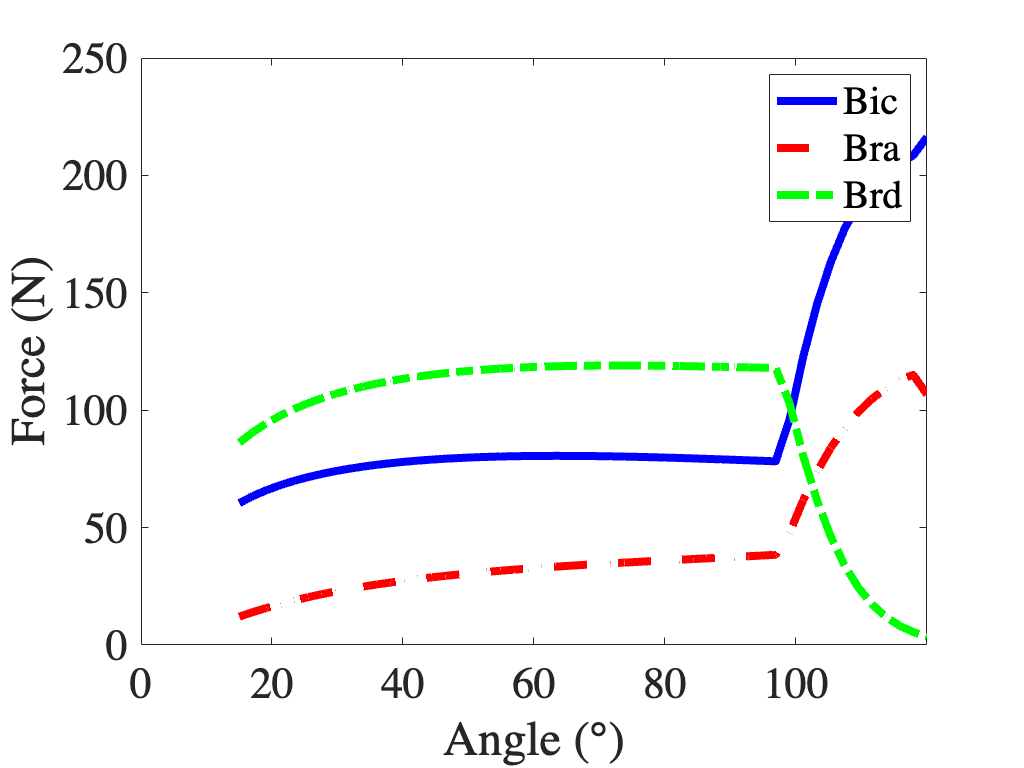

% Ploting F vs theta

% J1 cost function
plot(values_q(3,:)*180/pi,solution1(1,:),"LineWidth",4,"LineStyle","-","Color",'b')
hold on
plot(values_q(3,:)*180/pi,solution1(2,:),"LineWidth",4,"LineStyle","--","Color",'r')
plot(values_q(3,:)*180/pi,solution1(3,:),"LineWidth",4,"LineStyle","-.","Color",'g')
hold off

set(findall(gcf,'-property','FontSize'),'FontSize',18)
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'FontName','Times','fontsize',22)
xticklabels("auto")
yticklabels("auto")
xlabel('Angle (°)')
ylabel('Force (N)')
legend({'Bic','Bra','Brd'})

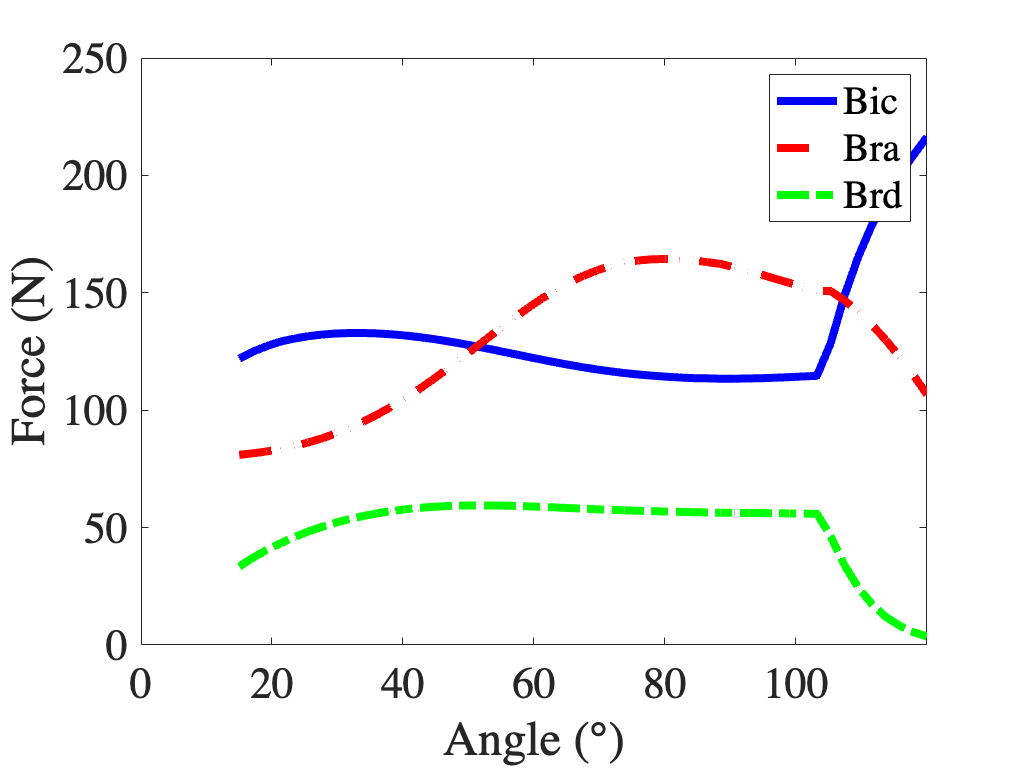



% J2 cost function
plot(values_q(3,:)*180/pi,solution2(1,:),"LineWidth",4,"LineStyle","-","Color",'b')
hold on
plot(values_q(3,:)*180/pi,solution2(2,:),"LineWidth",4,"LineStyle","--","Color",'r')
plot(values_q(3,:)*180/pi,solution2(3,:),"LineWidth",4,"LineStyle","-.","Color",'g')
hold off

set(findall(gcf,'-property','FontSize'),'FontSize',18)
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'FontName','Times','fontsize',22)
xticklabels("auto")
yticklabels("auto")
xlabel('Angle (°)')
ylabel('Force (N)')
legend({'Bic','Bra','Brd'})

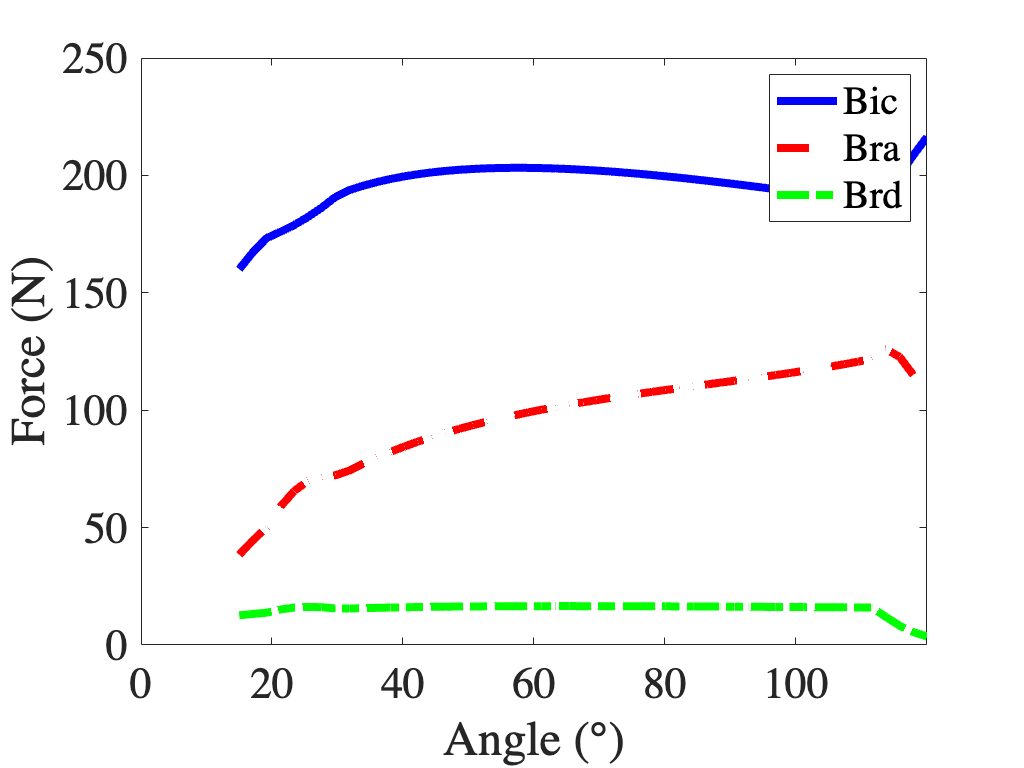



% J3 cost function
plot(values_q(3,:)*180/pi,solution3(1,:),"LineWidth",4,"LineStyle","-","Color",'b')
hold on
plot(values_q(3,:)*180/pi,solution3(2,:),"LineWidth",4,"LineStyle","--","Color",'r')
plot(values_q(3,:)*180/pi,solution3(3,:),"LineWidth",4,"LineStyle","-.","Color",'g')
hold off

set(findall(gcf,'-property','FontSize'),'FontSize',18)
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'FontName','Times','fontsize',22)
xticklabels("auto")
yticklabels("auto")
xlabel('Angle (°)')
ylabel('Force (N)')
legend({'Bic','Bra','Brd'})